# MOBATSim Documentation

Welcome to MOBATSim documentation. If you are new to MOBATSim, please check [GettingStarted.mlx](matlab:open('..\GettingStarted.mlx')) if you haven't already. If you have already completed your first simulation along with the tutorials and you want to learn more about the detailed implementations in MOBATSim, you are at the right place. Please read through the code as it only contains some snippets from the original code for explanatory reasons. You can execute the code in debug mode to step into the functions and go through reading the comments.

# The Workflow of the Simulation Framework

Automated driving systems tend to be more critical and sophisticated in the nearest future. The functional safety assessment for these systems becomes an urgent necessity for the transition to full autonomy. Testing these functions consisting of decision and control algorithms with many variables and parameters in a unified manner is a daunting task. Threat assessment has to be made for vehicles to avoid hazardous situations actively. This requires analyzing complex operational profiles such as routing, intersection management, and collision prediction in an environment where multiple vehicles are in different positions and traveling at different speeds. There is a need for a comprehensive traffic simulation framework that models not only the functionality of the vehicles but also the interactions between them.

As a solution, we offer a new simulation framework, MOBATSim, which is entirely based on MATLAB Simulink. It allows the user to customize decision and control algorithms for the modeled autonomous vehicles and analyze their effects on the overall safety of the high-level urban traffic environment. The user can define safety goals, derive functional safety requirements, describe driving scenarios, and verify if these goals are met for certain autonomous vehicle functions that are tested. The simulation-based fault injection is used to perform the tests in the presence of various types of random or predetermined faults of low-level vehicle components such as sensors and communication modules. The definitions of safety and controllability requirements of autonomous vehicle functions are derived from the safety standard ISO 26262. Automatically generated reports allow the user to save time and costs in the early design phase through comprehensive testing, and it can also prove a helpful framework to overcome the challenges of the adoption of ISO 26262. The data can be logged during the simulations and later be used by Simulink 3D Animation for visual investigations.

## The Process Flow Diagram

MOBATSim consists of m-files, MATLAB classes, and Simulink models. The initialization of the simulation framework starts with an m-file which prepares the required workspace variables, generates the map and the vehicles on a 2D plot, and opens the main Simulink model *src/Sımulınk Models/MOBATSim.slx*.  By running the Simulink model, the workspace variables that contain instances of the Vehicle Class, their parameters, intersection manager, and constant parameters required by the model are loaded. The main workflow of MOBATSim is shown abstractly in the figure below.

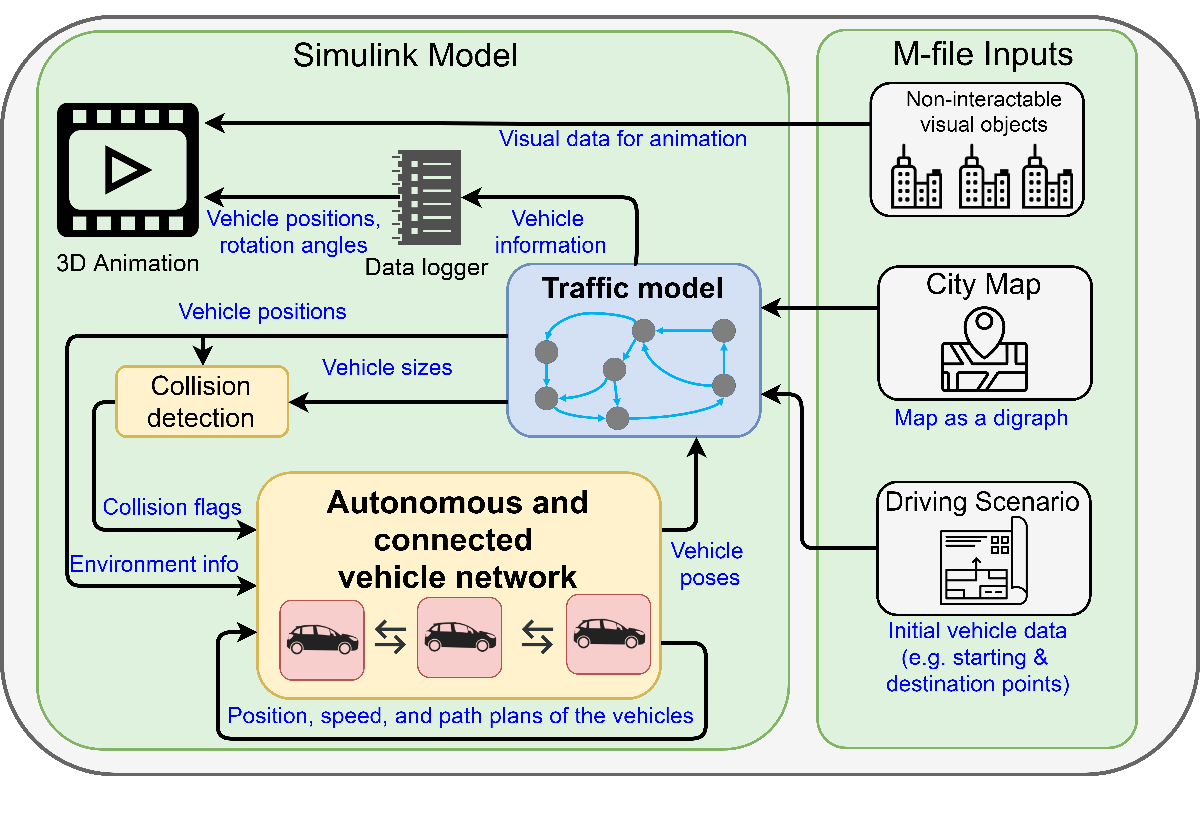

The initial parameters regarding the map and the driving scenario that will be simulated are stored in MATLAB m-files. These files contain information regarding the structure of the map and the initial parameters regarding the vehicles. Then this data is passed to constructor methods of the relevant classes to create an instance of the map and an array containing the instances of each vehicle to be simulated. The functional structure of the vehicle is mostly contained in the Simulink model, but some general methods for the vehicle class can be directly accessed. Once the initial traffic model is set up along with the vehicles, the Simulink model is opened and run to start the simulation. When the simulation starts, the MATLAB System Blocks found in the main Simulink model access the base workspace to use the Map and the Vehicle Objects by reference and change their fields at every sample time according to the working order of the Simulink blocks. The working order of the blocks can be seen by viewing priority property in Simulink. The Simulink model consists of both continuous models as well as discrete MATLAB System Blocks. Simulink automatically arranges the working order to ensure that the input is provided before the output is generated. More details about the functionality of these MATLAB System blocks will be explained along with their respective component or subsystem in the following chapters.

## Initialization Script

Init Script is called *src/Scrıpts/prepare_simulator.m*. It contains all the necessary variables for the workspace that are simulation parameters used by the model. It generates the map and vehicle objects as well as the initial 2D plot. If you click **Run **from the **LIVE EDITOR **section in the top-pane, the map will be plotted inline because of the live script. Normally the 2D plot appears as an external figure. To open it in an external window here, click on the small arrow on the top right corner (Open in figure window) of the map after it is generated.

prepare_simulator();

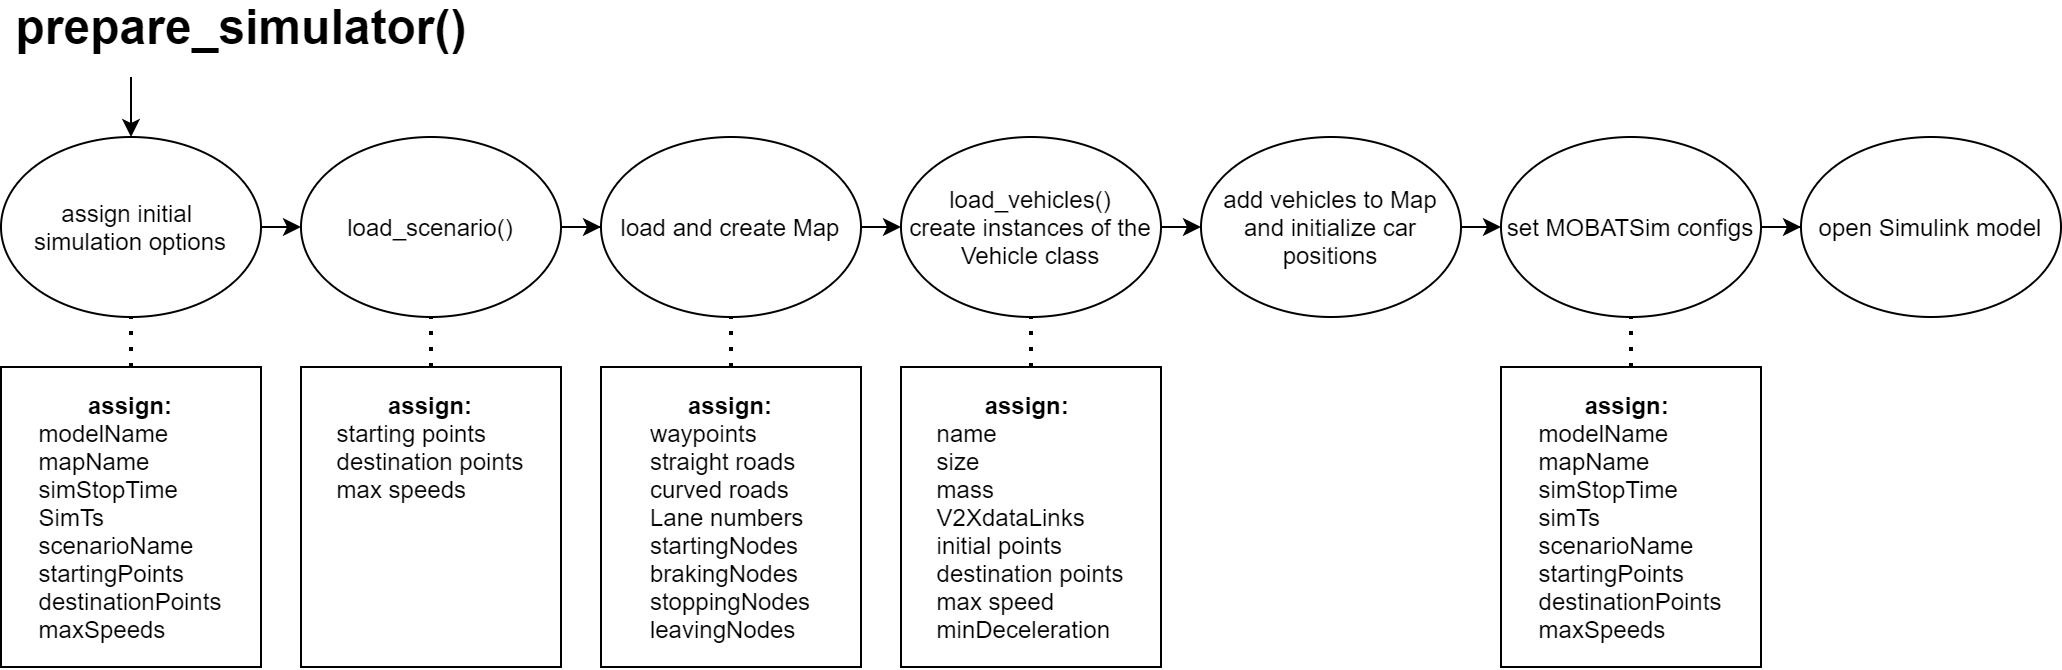

The 2D plot is later accessed by another function in Simulink during the runtime for dynamically updating it. The initial values are set as optional arguments for the function of the script. So if the user does not know what to enter for those parameters, the default values below are used. Therefore, it is not necessary to enter any input arguments when calling the `prepare_simulator()` function. For the code sections below, a **breakpoint** may be used to go **step-by-step (F10 or F11)** to learn the functionality better.

function prepare_simulator(options)
%% Init file for MOBATSim    
    % This function prepares the simulation
    %   After calling this function the simulation can run
    arguments
        options.modelName           (1,1) string    = 'MOBATSim'            % Name of the simulink model
        options.mapName             (1,1) string    = 'Mobatkent'           % Name of the map
        options.simStopTime         (1,1) double    = 80                    % Simulation stop time in seconds
        options.simTs               (1,1) double    = 0.02                  % Simulation time step: sample time of the simulation (may not be stable if changed)
        options.scenarioName        (1,1) string    = 'Urban City Traffic'  % Scenario sets start points, destination points and maxSpeeds
        options.startingPoints      (1,:) double    = []                    % Custom starting points for vehicles
        options.destinationPoints   (1,:) double    = []                    % Custom destination points for vehicles
        options.maxSpeeds           (1,:) double    = []                    % Custom max speeds for vehicles
    end
       
    hold off
    warning off

The initial values for the `simStopTime` are set as **80** seconds above. The Simulink model uses these values as the simulation time parameter. The default sample time for the blocks in the Simulink model is set by the `simTs` variable, which is equal to **0.02** seconds by default. The other parameters will be explained where they are used in the following sections. Some variables are for enabling some other optional features such as `option.Analysing` and `option.simpleMap`. These parameters do not affect the main simulation and are neglected in this documentation. 

### Driving Scenario and the Vehicles

Next step is to load the `driving scenario` and initialize the `Vehicles`.

%% Load Scenario
[startingPoints, destinationPoints, maxSpeeds] = load_scenario(options.scenarioName);

%% Clear all data and release maps including invisible handles to make sure that the simulations can be repeated
if evalin('base','exist(''Map'',''var'')')
    evalin('base','clear all');
    evalin('base','close all');
end

%% Load the Map
[Route_LaneNumber, waypoints, connections_translation, connections_circle, ...
    startingNodes, brakingNodes, stoppingNodes, leavingNodes] = load_Mobatkent_from_opendrive();%load extended map

%% Generate the 2D Map and the instance from the Map class
Map = GridMap(options.mapName,waypoints, connections_circle,connections_translation, startingNodes, brakingNodes, stoppingNodes, leavingNodes,Route_LaneNumber,"showLaneNumbers",true);

[Click here to learn more about the Map superclass in MOBATSim.](matlab:open('..\src\Models and Classes\Maps\Map.m'))

[Click here to learn more about the GridMap class in MOBATSim.](matlab:open('..\src\Models and Classes\Maps\GridMap.m'))

%% Load Vehicles
Vehicles = load_vehicles(startingPoints, destinationPoints, maxSpeeds, Map);

We have the map and the vehicles as separate objects; now, we have to insert these vehicles into the map.

%% Initialize Vehicles on the Map
Map.Vehicles = Vehicles;
Map.initCarDescriptionPlot();

After setting all the necessary initial values and instances, the Simulink model is ready to start the simulation. It is worth mentioning that we have two types of classes. In the *src/* directory, you will find **MATLAB classes** and **Simulink classes**. The Simulink classes are used for the **MATLAB System Blocks** in the Simulink models. Therefore, they are of a specific type, and their structure is a bit different from the standard classes of MATLAB. However, we can use instances from the MATLAB classes inside the Simulink classes by reference.

[Click here to learn more about the Vehicle class in MOBATSim.](matlab:open('..\src\Models and Classes\Vehicle.m'))

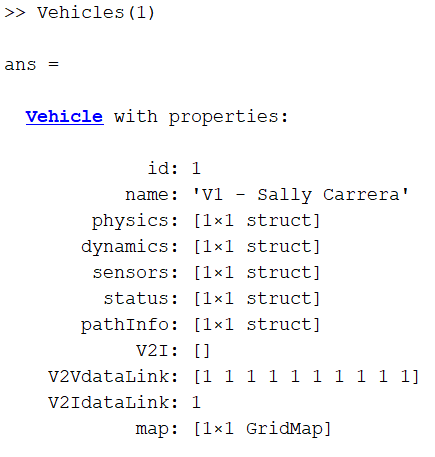

Right after the Simulink model is opened, a 2D plot will appear in a new window and automatically maximize to fullscreen. The details about how the map is generated, its specific structure, the underlying algorithms, and the map format are explained in a later section.

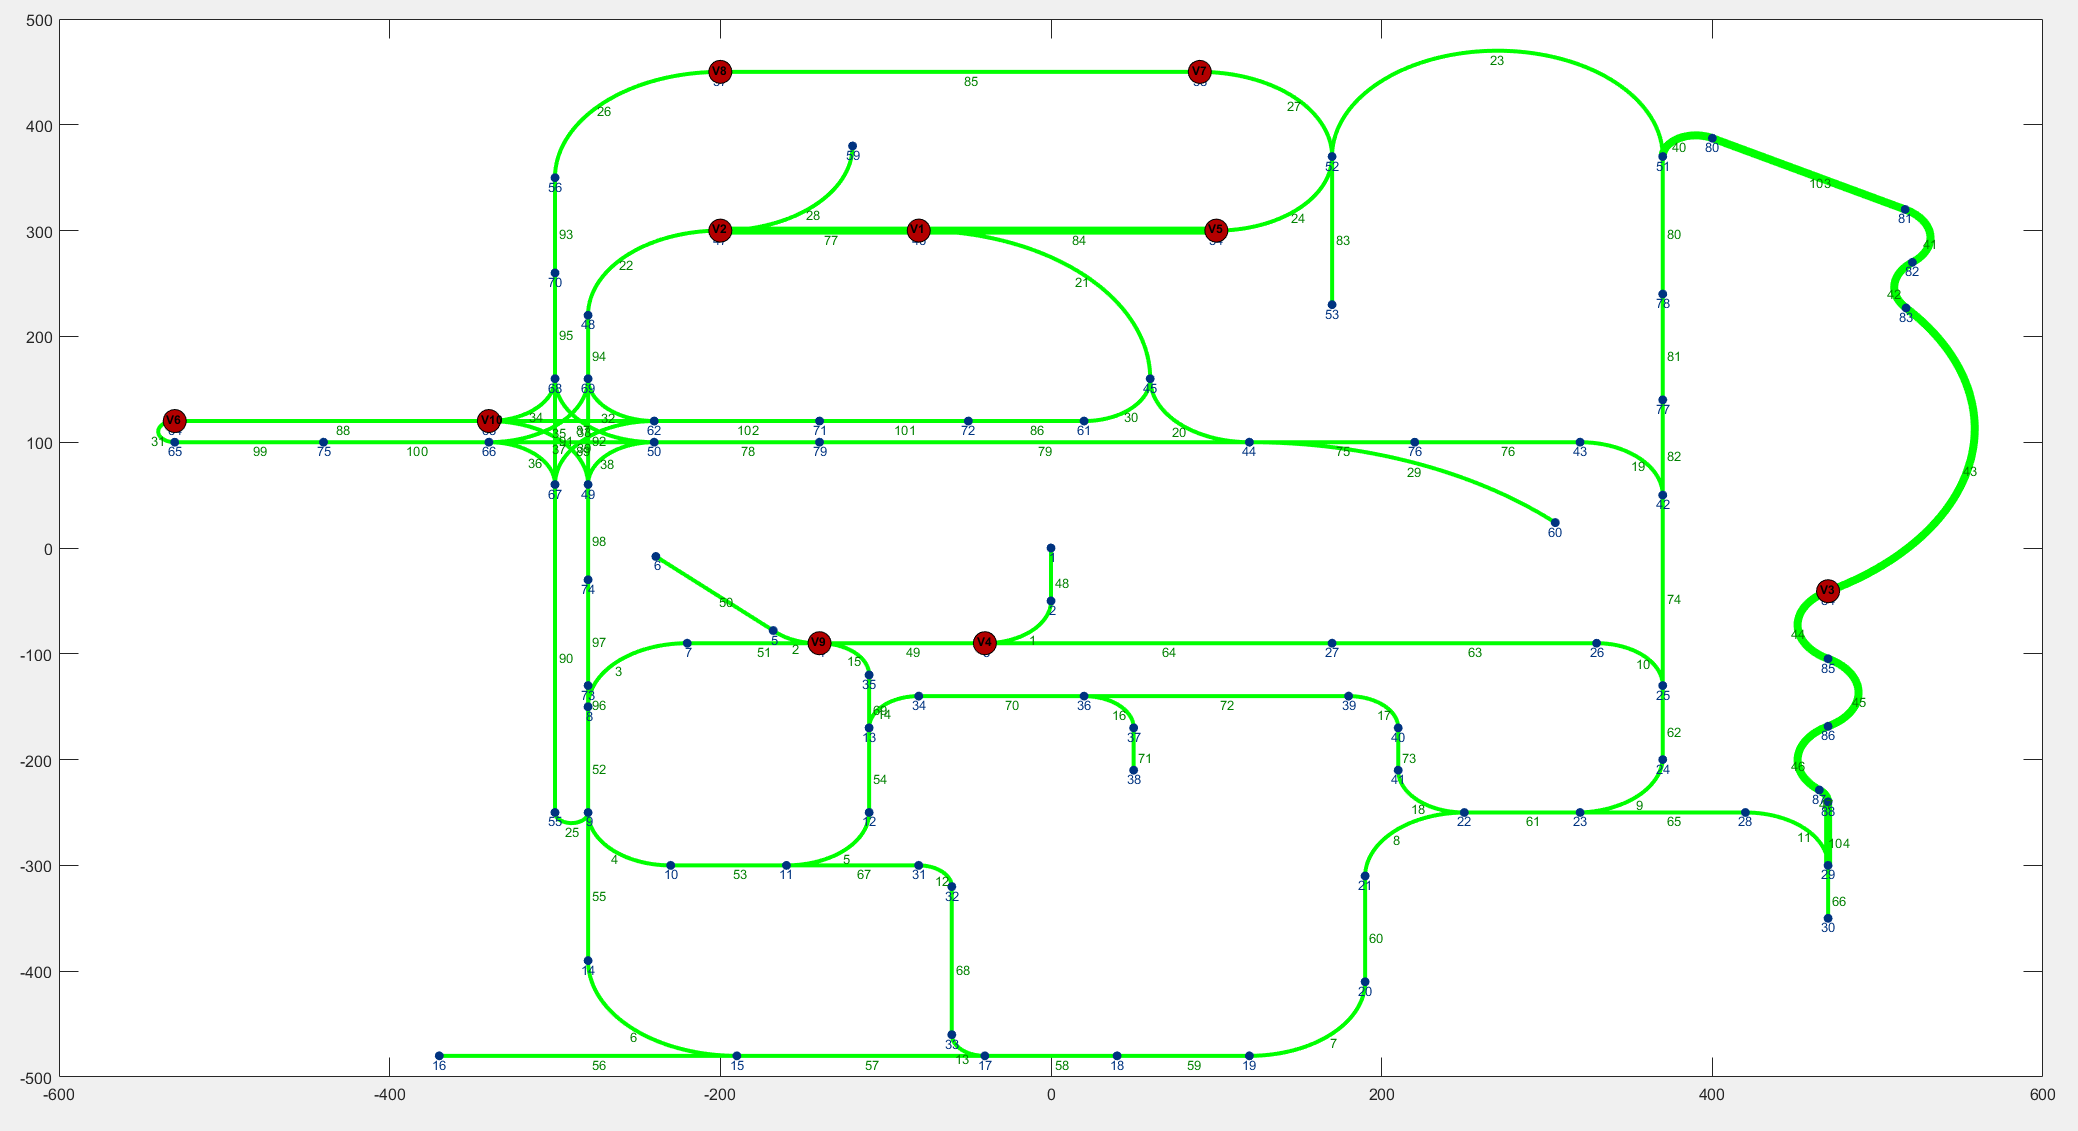

### The Traffic Model and 2D Visualization

The traffic model of MOBATSim used to be an m-file that contained checkpoints and the routes between these points. The structure was converted into a **digraph** consisting of **nodes** and **edges**. The **nodes** are the points that are then used by the vehicles as **starting** and **ending** **points**. The **edges** are the **routes** between these nodes and are defined either as **straight** or **curved** roads. 

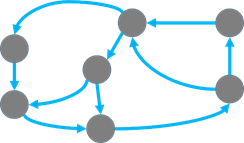

A **digraph** (directed graph) is a graph consisting of nodes and edges. In the **MOBATSim 2D Plot**, **edges** depict one-way routes illustrated with **green**, and the **nodes** depict waypoints shown as **blue dots**.

The **Path Planner** component of the vehicle *(which will be explained in the following sections)* uses its pathfinding algorithms to derive a path, which is a set of nodes and edges to reach the destination node. After determining the Path, the nodes in the Path array are used by the **Local Trajectory Planner** component of a vehicle to determine their desired trajectory and to track their planned route. The **Mobatkent map** plotted as a digraph, **shown in the 2D plot figure below**, displays the traffic simulation during the simulation runtime allowing faster simulation in the first place for the data logging. Once the simulation stops and the data is logged, more sophisticated visualizations such as Bird's Eye View or Unreal Engine 4 support can be used. The algorithm for plotting the roads and the vehicles is explained here: [Click here to learn more about how the 2D Map in MOBATSim is generated.](matlab:open('./MapGeneration2D.mlx'))

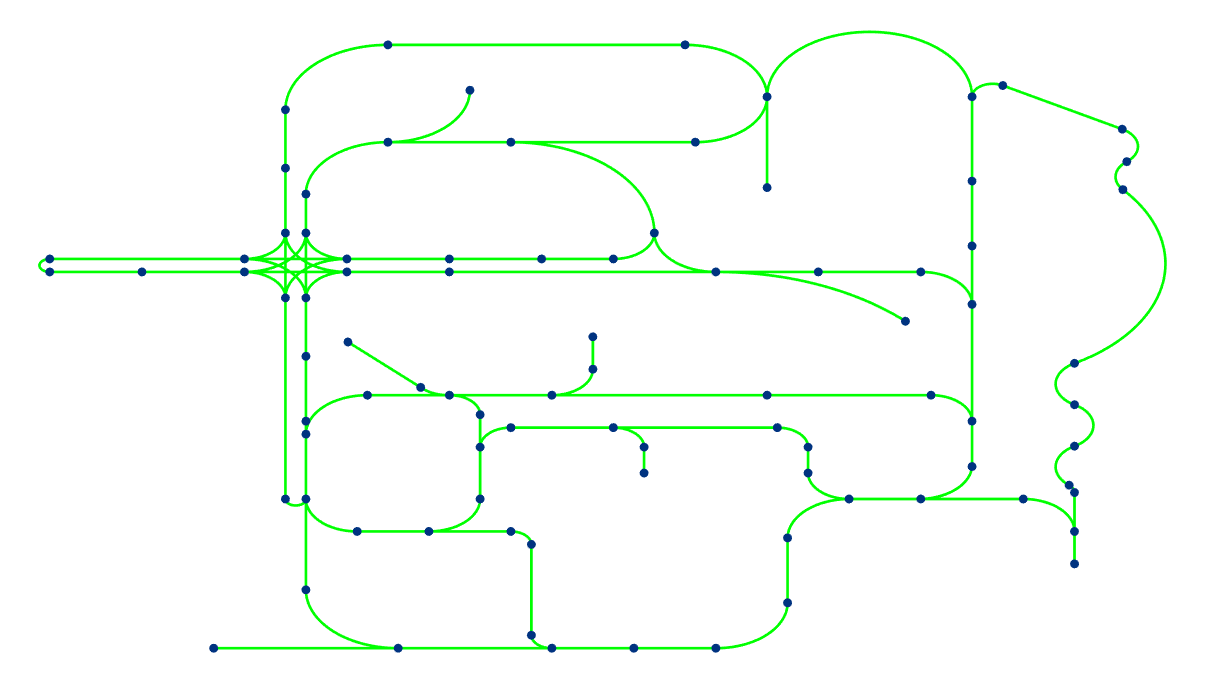

The planning of the **Mobatkent map** was initially done in **SolidWorks 2D Sketch**. The geometric properties of the routes were defined, and then the sketch was transformed into an m-file. This m-file contained the node positions in cartesian coordinates and the information regarding the edges (as either straight or curved roads). The road structure defined in the 2D sketch was made 3D using **SolidWorks** and then exported into the** virtual world format** for the **MATLAB V-Realm Editor**.

**New Feature with Version 2.0: **The old map is redrawn and updated in the **Driving Scenario Designer App** with double lane roads and more extensions. **Driving Scenario Designer App** is a built-in tool of MATLAB and uses the **OPENDrive format** to define the road structures. Conversion algorithms were developed to transform the coordinate system used in the OPENDrive format to the MOBATSim map structure. Thanks to this update, the map extension can easily be done using the **Driving Scenario Designer App**.

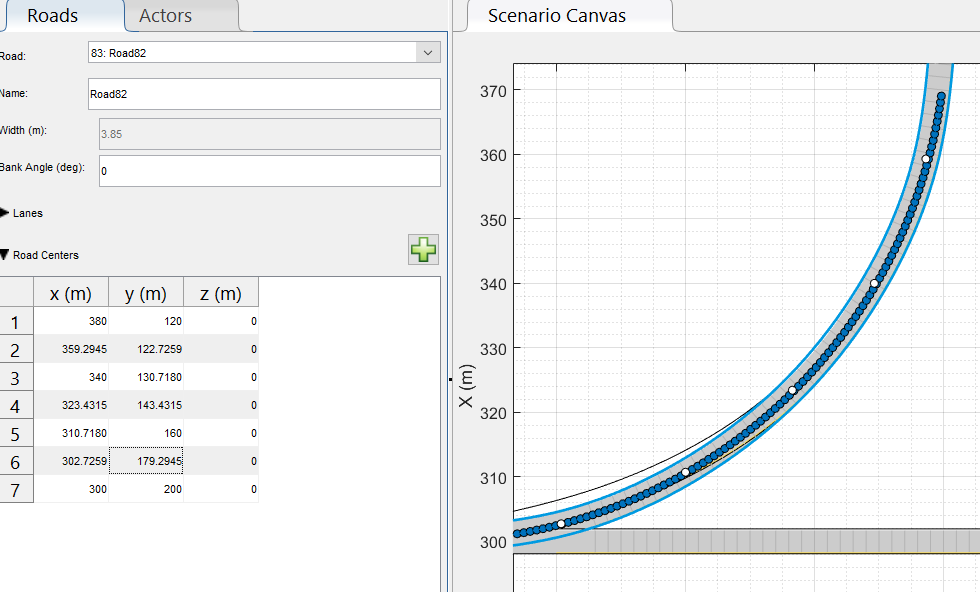

For more details: [Click here to learn more about the 2D Map extension, map transformation algorithms, and how it is visualized using Unreal Engine.](matlab:open('./MapExtension3DVisualization.mlx'))

# The Main Simulink Model

The complete Simulink model is shown below. In the following chapters, the content under the subsystem blocks will be shown in detail. As we focus on the model, we see some colored areas grouping some of the elements. The green area on the left denotes the Vehicle Models. By default, MOBATSim has 10 Vehicles, but in a later chapter, we show how the number of vehicles can be changed easily by adding another vehicle.

% Open the MOBATSim Simulink Model
open_system(options.modelName)

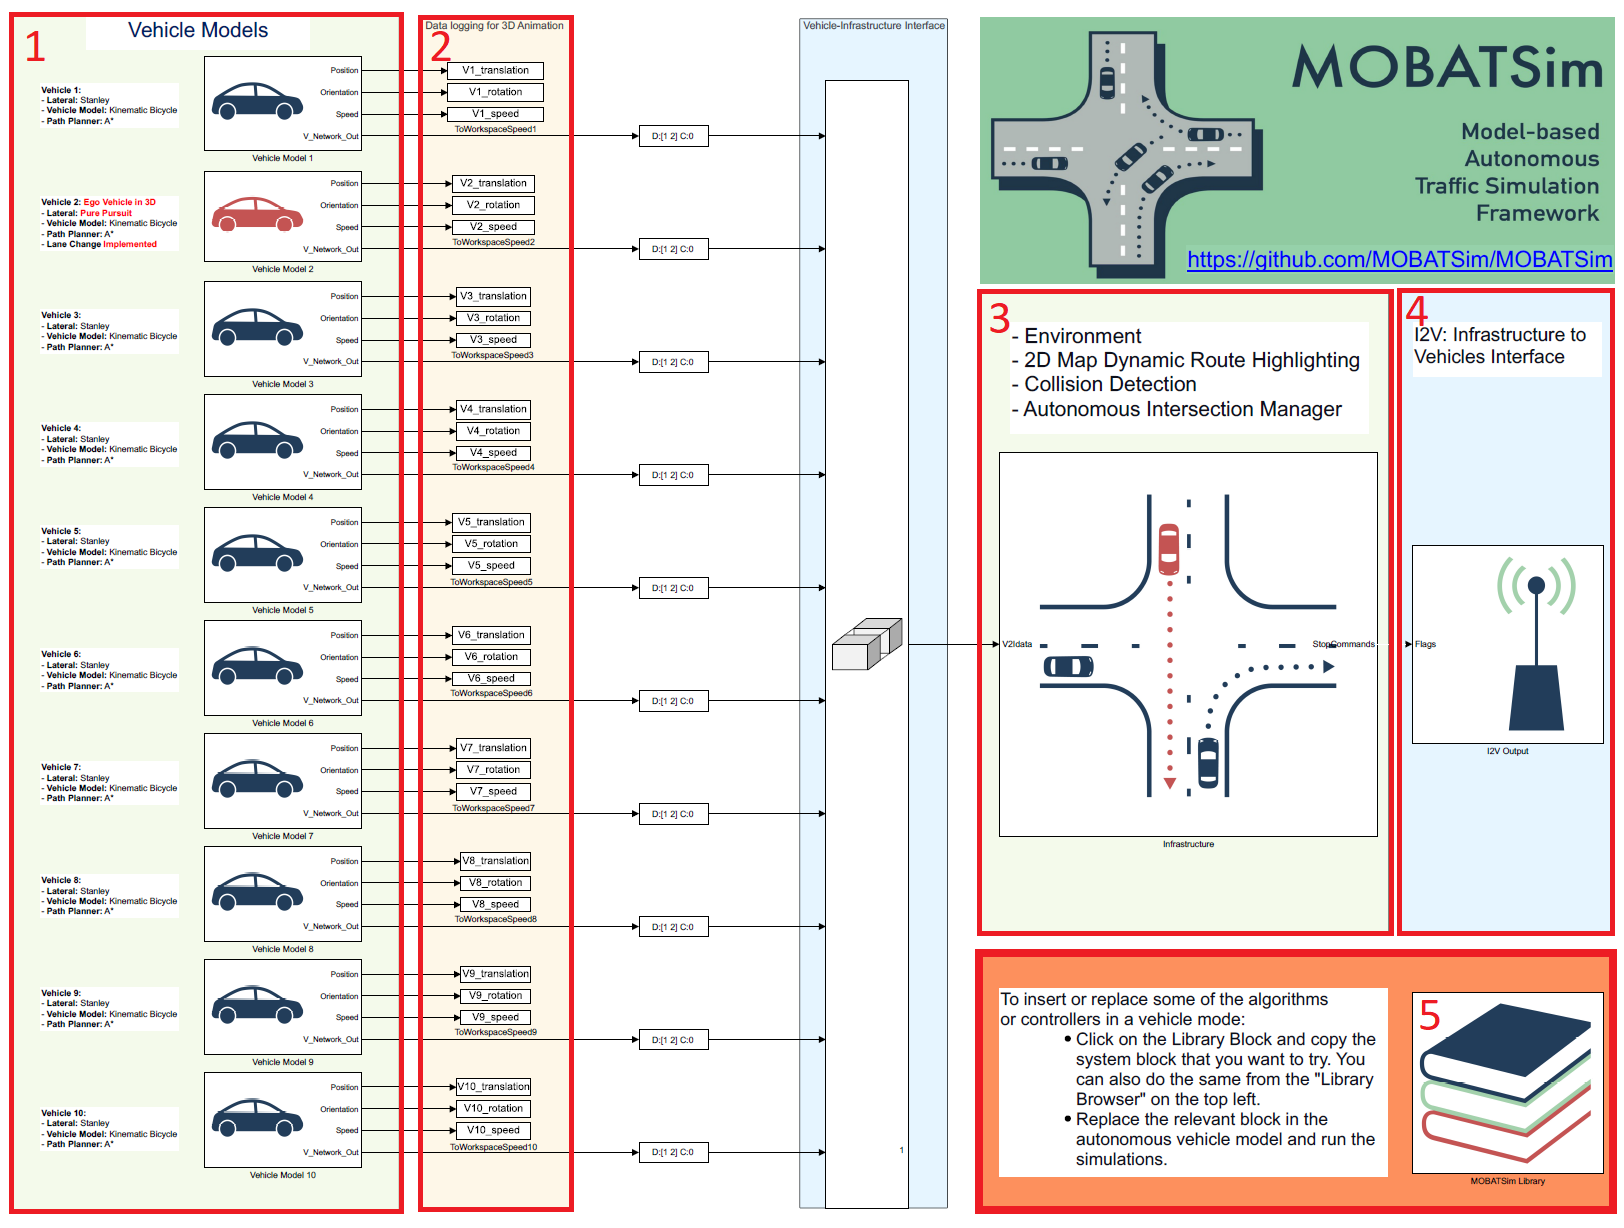

The sections illustrated with a red rectangle will be the focus of the next chapter. We can summarize the elements of the top-level Simulink model as:

- **Autonomous Vehicle Models - Masked Subsystem Blocks**

- **Data Logging for later 3D visualization**

- **Infrastructure (Environment) MATLAB System Block**

- **I2V Interface from the Autonomous Intersection Manager to Vehicles**

- **MOBATSim Simulink Block Library**

The dependency analysis of the whole project is shown in the chart below:

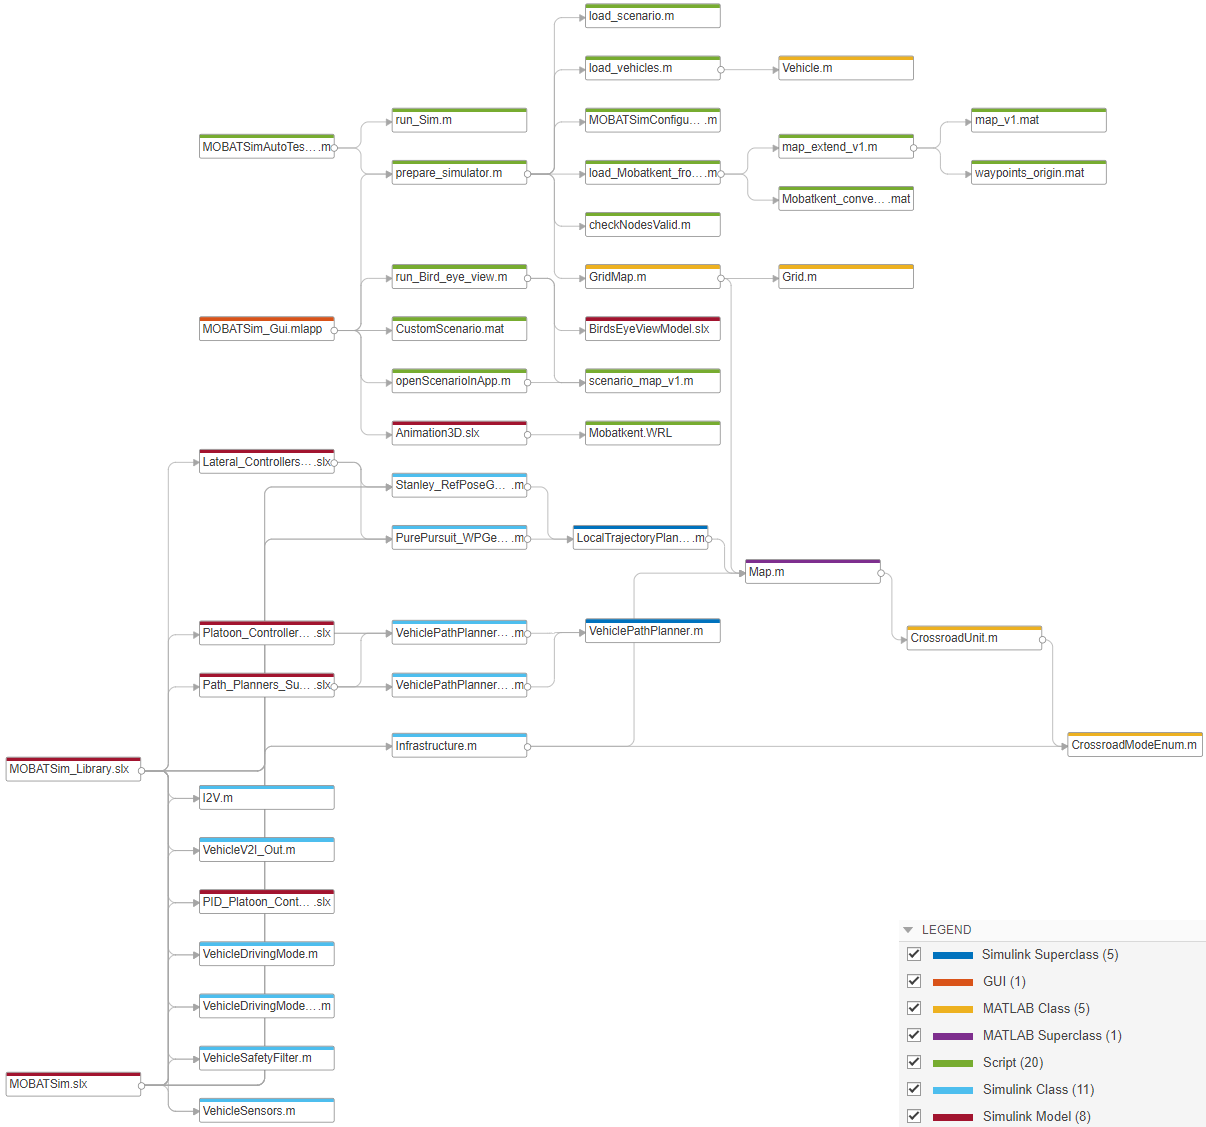

There are many configurations and customizations for MOBATSim, which you can easily understand by going through the code, but we will focus mainly on the fundamental elements in this documentation. After all the variables are generated, they are saved to the workspace with the `assignin` function. Some other code lines are skipped for simplicity in this documentation, but descriptive comments can be found in the m-files.

    %% Make a MOBATSim Configuration
    configs = MOBATSimConfigurations(options.modelName, ...
                                     options.mapName, ...
                                     options.simStopTime, ...
                                     options.simTs, ...                                     
                                     options.scenarioName, ...
                                     startingPoints, ...
                                     destinationPoints, ...
                                     maxSpeeds, ...
                                     false, ...
                                     false);
        

    %% Assign all needed workspace variables to the "base" workspace
    assignin('base','Sim_Ts',options.simTs);        % Used as the block sampling time
    assignin('base','Sim_t',options.simStopTime);   % Used by the model as the Simulation Time
    assignin('base','configs',configs);             % MOBATSim configurations
    assignin('base','Map',Map);                     % Used by the Infrastructure.m
    assignin('base','Vehicles',Vehicles);           % The instances are used by the MATLAB System Blocks
end

At this moment, the simulation environment is ready to run. You can go back to the Simulink model and click **Run** to start the simulation or execute the script `Run_Sim()` which has the following line of code to run the model from the base workspace:

# ---------------------------------------------------------------------------------

# Structure and Design of MOBATSim

## 1- Autonomous Vehicle Models

The structure of an autonomous vehicle in MOBATSim consists of different abstraction levels. The reason for this abstraction is to allow the user to easily access and customize the low-level components, their inputs/outputs, and the implemented decision and control algorithms by clear interfaces between these components and subsystems shown in the figure below. There are four main interfaces: Perception, Decision-making, Control, and Communication Output.

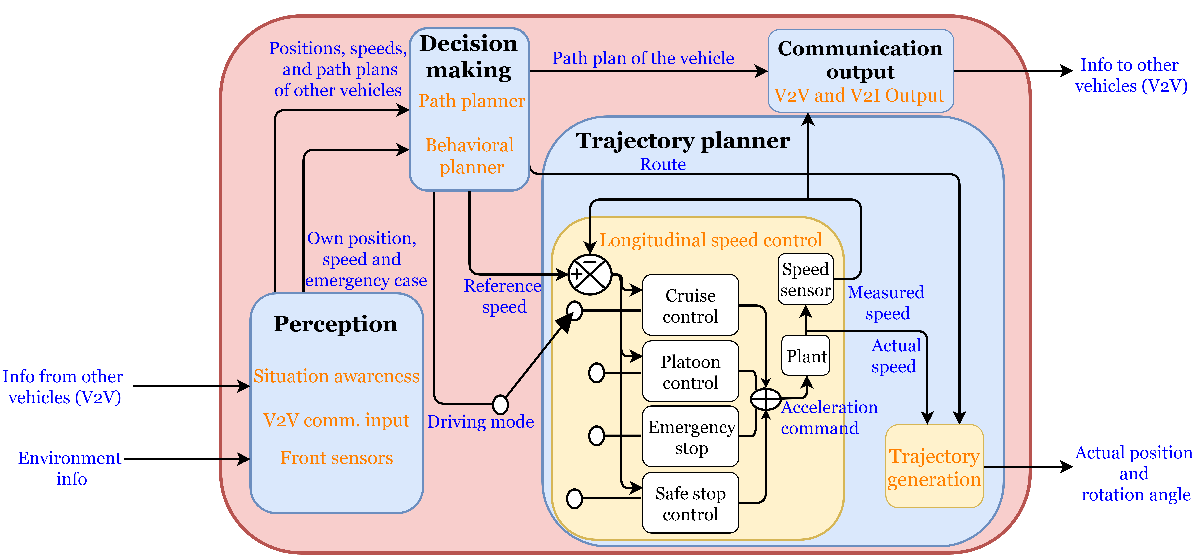

There are two main sources where the logic gets executed. One of them is the `.m file` scripts, and the other ones are the Simulink models of the vehicles. They both work coordinated, as Simulink blocks use the created instances from the `Vehicle `class and overwrite their values. When you click on the small arrow on the lower-left corner of a **Vehicle** **block**, you should get the **underlying subsystem model** as shown in the block diagram below:

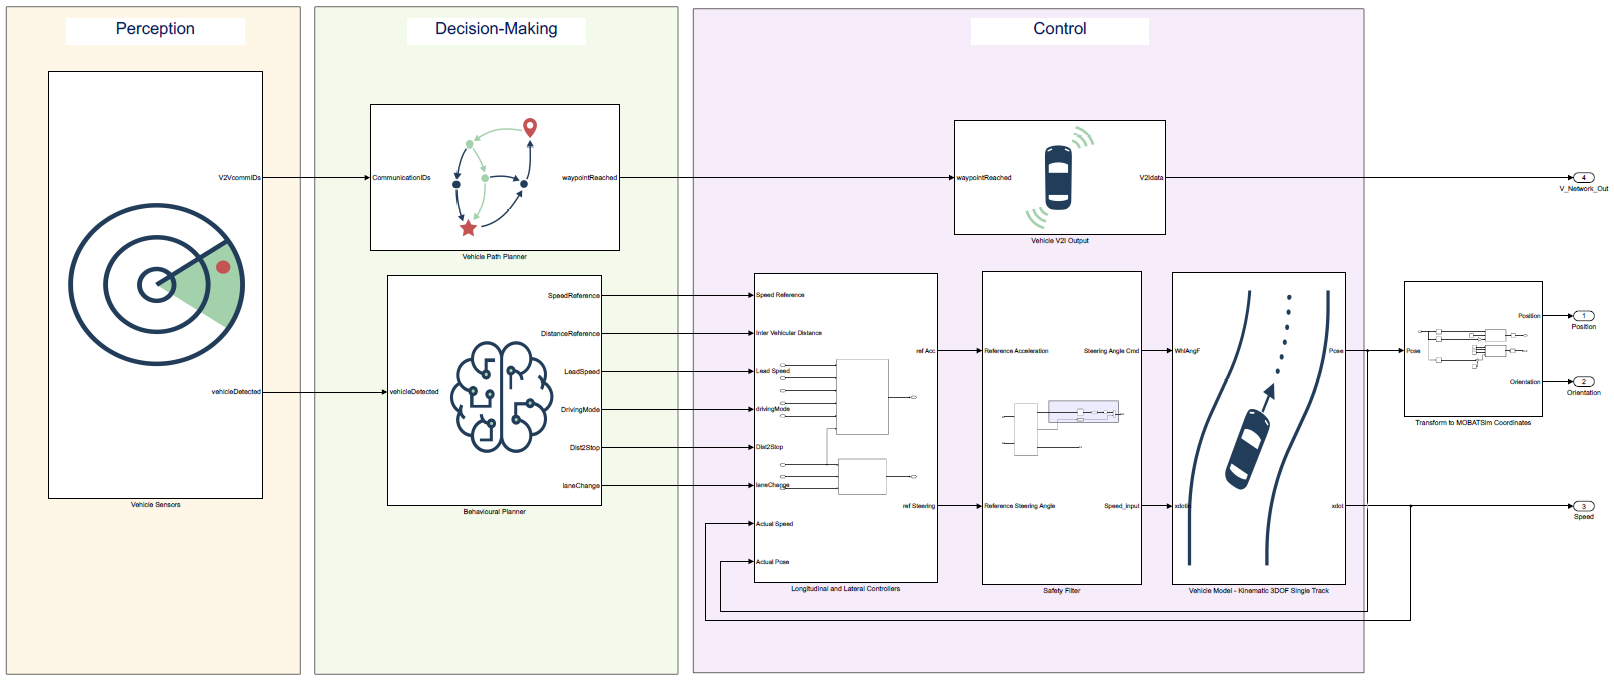

From here on, there are two main types of blocks. The first one is the **MATLAB System Blocks**, which takes **Simulink signals as inputs** and **runs MATLAB codes** and **output signals**. To see the code, double-click on the block and click on the source code.

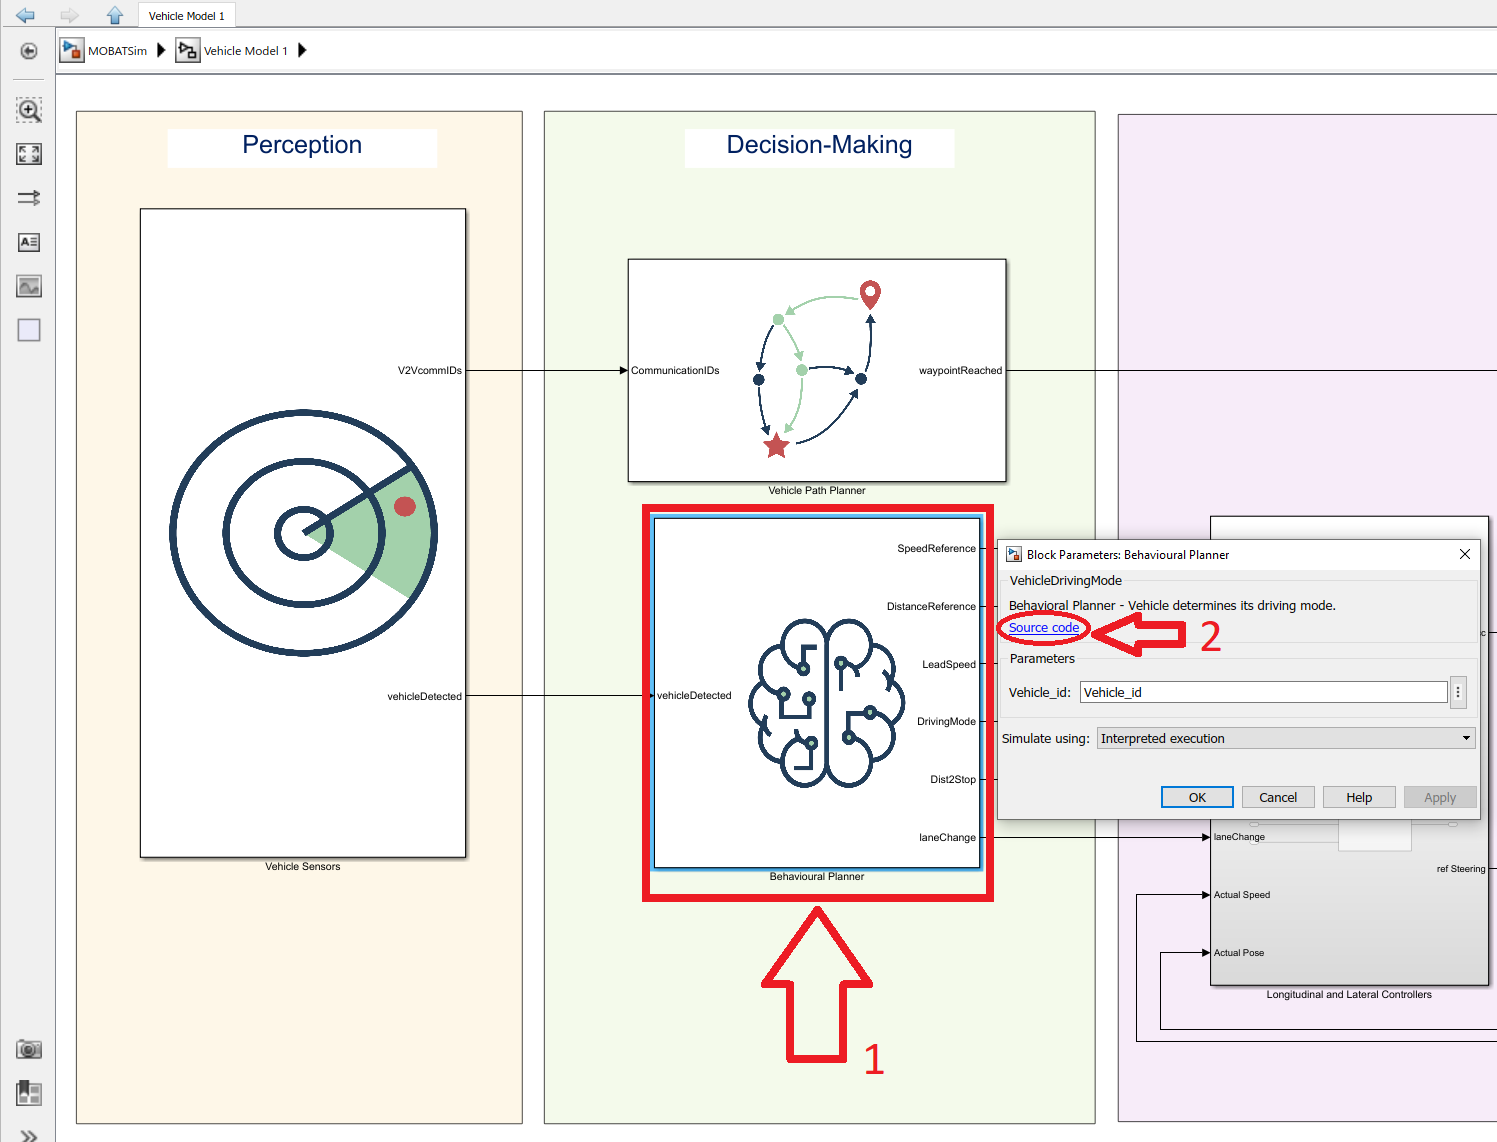

### Perception Interface

#### Vehicle Sensors Block - `VehicleSensors.m`

Autonomous vehicles in MOBATSim perceive their environment and the other vehicles using their sensors. The sensor model is not concretely defined to leave room for flexible development but can be mainly considered an ideal radar implementation measuring distances to the nearby vehicles and a V2V communication component. The **VehicleSensors block** runs accessing and using the ground truth data from the simulation, which contains the other vehicles' positions and V2V shared data; hence it does not have any Simulink input port.

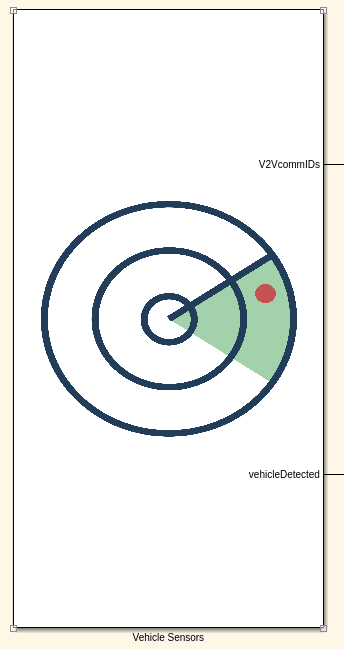

The tunable properties are of the `Vehicle_id`, `Tsample`, `OffsetTime`.

`Vehicle_id` property is used to parametrize the sensor of each vehicle. Every vehicle got its own sensor block `VehicleSensors.m`. The `VehicleSensors` block is used to locate the nearest vehicle in front and behind itself. The detection will be made in each simulation step. There can be four cases:

- no rear vehicle detected, no front vehicle detected

- no rear vehicle detected, front vehicle

- rear vehicle detected, no front vehicle detected

- rear vehicle detected, front vehicle detected

Possible outcomes :=$\left\lbrack \begin{array}{cc}
\emptyset ,\emptyset  & \emptyset ,V_f \\
V_r ,\emptyset  & V_r ,V_f 
\end{array}\right\rbrack$

The detection functionality is realized by first checking the route segment that the vehicle is on; if detected, the vehicles are registered. If no front vehicle is detected, then the adjacent next route is checked for any vehicles ahead. If found registered, if not `-1` value returned for no detection. Rear vehicle detection is realized likewise by checking the adjacent previous route segments.

`stepImpl(obj) `function is the main function that runs at every sample time. It takes no input from Simulink and only uses the assigned properties, which allows it to reach all the data about the other vehicles on the map. It creates two outputs `[V2VcommIDs, vehicleDetected] `for the subsequent blocks. Some of the helper functions are listed below:

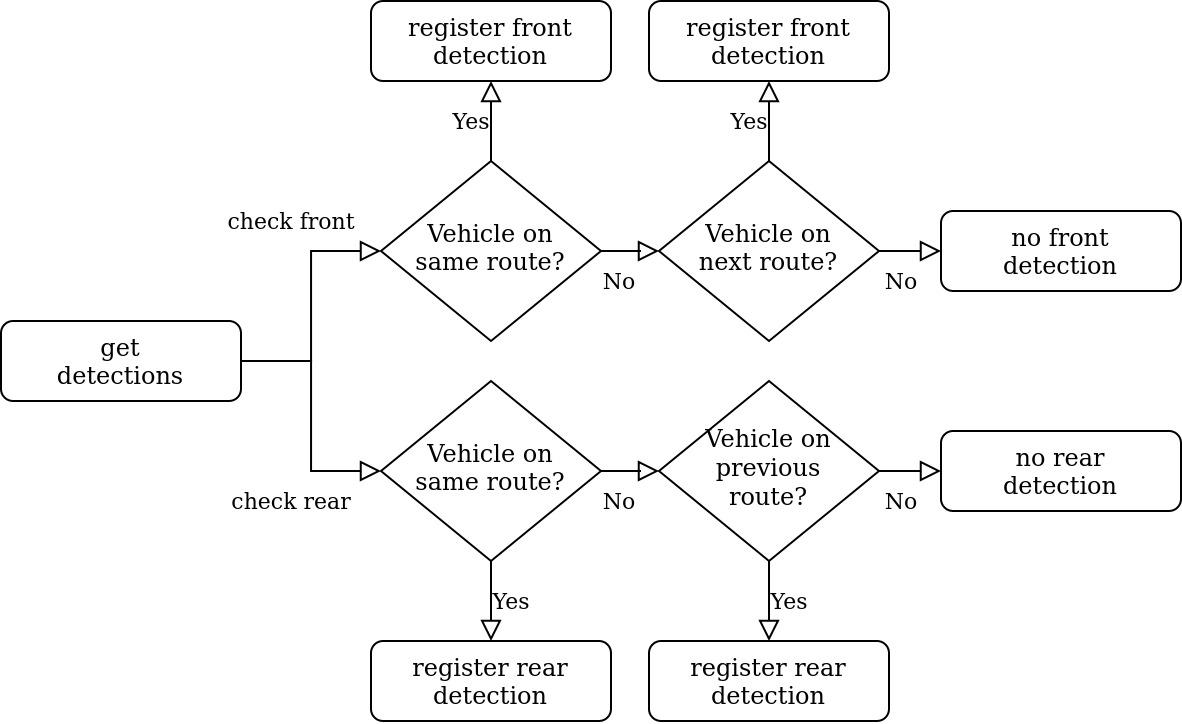

[Click here to view the source code of the VehicleSensors.m class](matlab:open('..\src\Models and Classes\VehicleSensors.m'))

### Decision-Making Interface

The decision-making part consists of a **Path planner** and a** Behavioral planner**.

#### Vehicle Path Planner Block - `VehiclePathPlanner.m`

The **Path Planner** block uses estimation and pathfinding algorithms to decide the route to be taken by the vehicle.

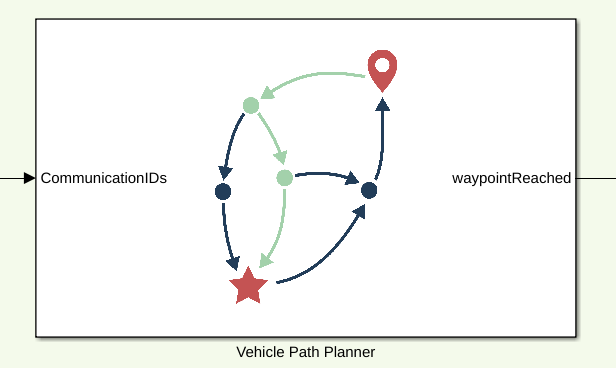

[Click here to view the source code of the VehiclePathPlanner.m class](matlab:open('..\src\Models and Classes\PathPlanners\VehiclePathPlanner_Astar.m'))

#### Vehicle Behavioral Planner Block - `VehicleDrivingMode.m`

The **Behavioral Planner** block takes the input data about the perceived situation of the vehicle and generates the driving command inputs to determine the **driving mode of the vehicle** (e.g., **cruise control**, **platooning**, **lane-changing maneuver**, **emergency brake**, **approaching an intersection**). According to the driving mode, the relevant subsystem of the longitudinal and lateral controllers adjust the acceleration and the steering commands to follow the planned trajectory.

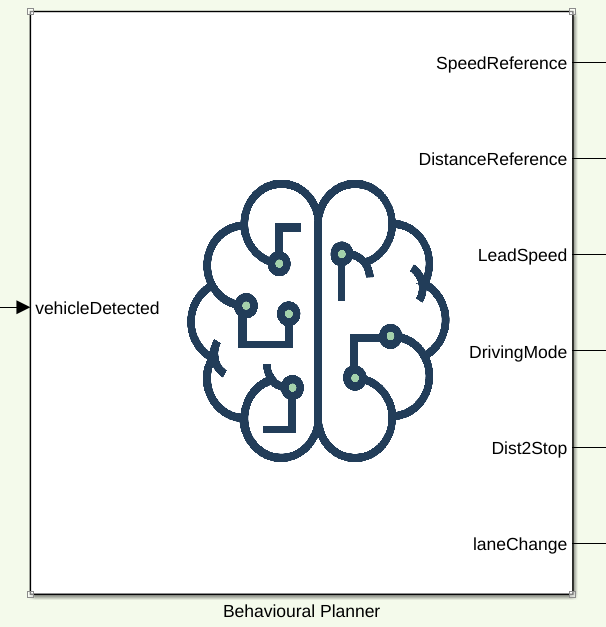

[Click here to view the source code of the VehicleDrivingMode.m class](matlab:open('..\src\Models and Classes\VehicleDrivingMode.m'))

### Control Interface

The Control interface consists of a Behavioral Planner, which decides the driving modes depending on the situational awareness and generates optimal trajectories, and a Longitudinal & Lateral control subsystem. The Longitudinal & Lateral control subsystem exhibits the commanded driving behavior and tracks the optimal trajectory if received. There are mainly four driving modes available: cruise control, platooning control, safe stop control, and emergency stop. There is also a switch from platooning control mode to lane-changing maneuver if possible, necessary, safe and realizable.

Cruise control is the mode where there is no vehicle ahead. In this mode, the vehicle accelerates to reach its top speed. As long as the front sensor does not sense any vehicle ahead or the V2I component of the vehicle does not receive a stop message before an intersection, the vehicle keeps going at its top speed.

When the vehicle has to follow a slower vehicle, the platooning control takes over to generate the acceleration commands to form a stable platoon. Several algorithms can be implemented for following a vehicle and keeping a safe distance. At the moment, MOBATSim offers three variations: constant space by PID, constant headway time by PID, and constant headway time by MPC. All these control algorithms can be tuned to implement more aggressive or more robust vehicle following behaviors.

Safe stop control starts where the vehicle receives a stop message and has to stop before an intersection if the other vehicles have the right to cross the intersection. It helps vehicles slow down softly before a designated stop node.

The emergency stop utilizes full brakes when the vehicle ahead stops suddenly, or another vehicle suddenly cuts in. Then the emergency-stop part generates a constant deceleration command.

The selected route and the longitudinal speed are taken as inputs by the trajectory generation component to create the longitudinal and rotational motions. A pose vector consisting of an x-y-z coordinate position and a rotation angle is created for the simulation.

#### Difference between Vehicle 2 and the other Vehicles

Vehicle 2 is chosen as an experimental vehicle to make sure that the designing process focuses on a single vehicle in the first place to try new things. After testing it thoroughly and ensuring that the newly designed algorithm or a controller works as desired, it can be copy-pasted into some other vehicles to view the results on the traffic scale. At the moment, there are two local trajectory planners that create the output that is necessary for the lateral controller. Lane-changing behavior is only implemented in Vehicle 2, which has a **Pure Pursuit** **Controller** for lateral control, whereas the other vehicles have a **Lateral Stanley Controller**.

**1- Stanley Reference Pose Generator**

In every vehicle except for **Vehicle 2**, the lateral movements are controlled using the **Lateral Stanley Controller**. Detailed documentation with reference examples from MathWorks can be seen here: [https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html](https://www.mathworks.com/help/driving/ref/lateralcontrollerstanley.html).

The required inputs for this block are the **Reference Pose**,** Current Pose**,** Current Velocity**, and** Direction**. The current pose and velocity information are obtained from the output of the kinematic bicycle model of the vehicle at every sample time as it is being simulated for motion. In MOBATSim, only forward motion is allowed at this moment, so the Direction variable is a constant positive "`+1"`. For backward motion, "`-1"` is needed. The most challenging input required for the** Lateral Controller Stanley** block is the **Reference Pose** variable. This variable depends on the desired position on the road at every sample time. As explained in the reference link above, it is defined by the point that is on the reference path and is the closest at a given time to the vehicle's front axle. Note that the lane-changing maneuver is disabled for this lateral controller in MOBATSim as it requires further testing before being deployed.

[Click here to view the source code of the Stanley_RefPoseGenerator.m class](matlab:open('..\src\Models and Classes\LocalTrajectoryPlanners\Stanley_RefPoseGenerator.m'))

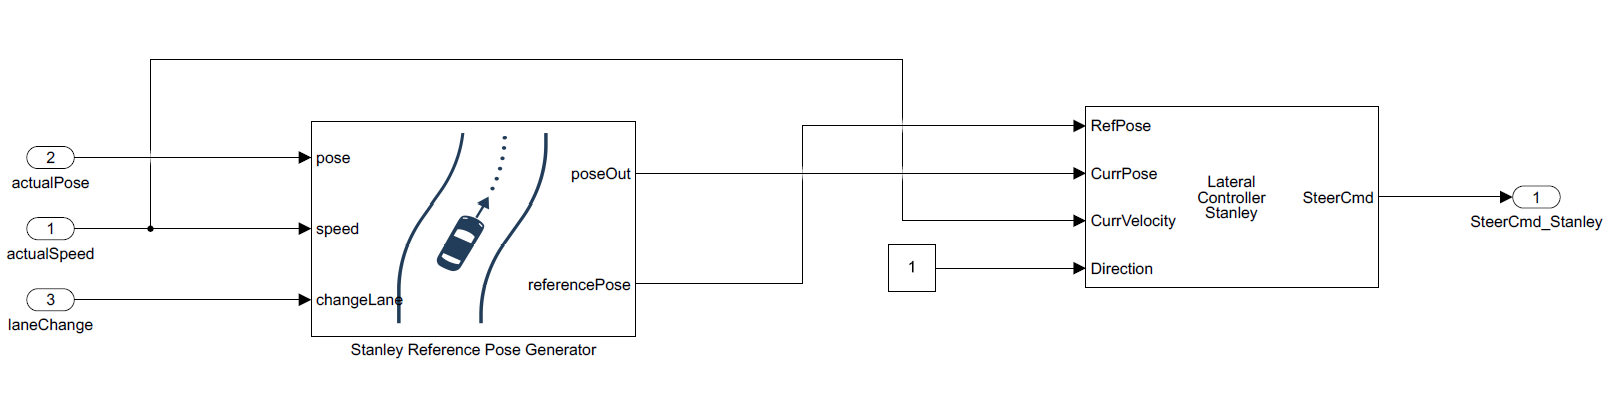

**2- Pure Pursuit Waypoint Generator**

Another lateral controller is the **Pure Pursuit block** which takes the **current pose** of the vehicle and the **waypoints** that it has to pass through. From these two information, where the waypoints can be an array of waypoints defined in cartesian coordinates, the Pure Pursuit block derives the target direction by creating a smooth curve between these points according to its look-ahead distance. Then this reference direction angle is passed onto a subsystem which converts it into wheel steering angle, as the kinematic bicycle model works with the steering angle input. In MOBATSim, at this moment, only Vehicle 2 has the Pure Pursuit lateral controller and also the lane-changing capabilities. Using a **Frenet Coordinate Frame**, **Vehicle 2** can smoothly make lane-changing and overtaking maneuvers on both straight and curved double roads.

[Click here to view the source code of the PurePursuit_WPGenerator.m class](matlab:open('..\src\Models and Classes\LocalTrajectoryPlanners\PurePursuit_WPGenerator.m'))

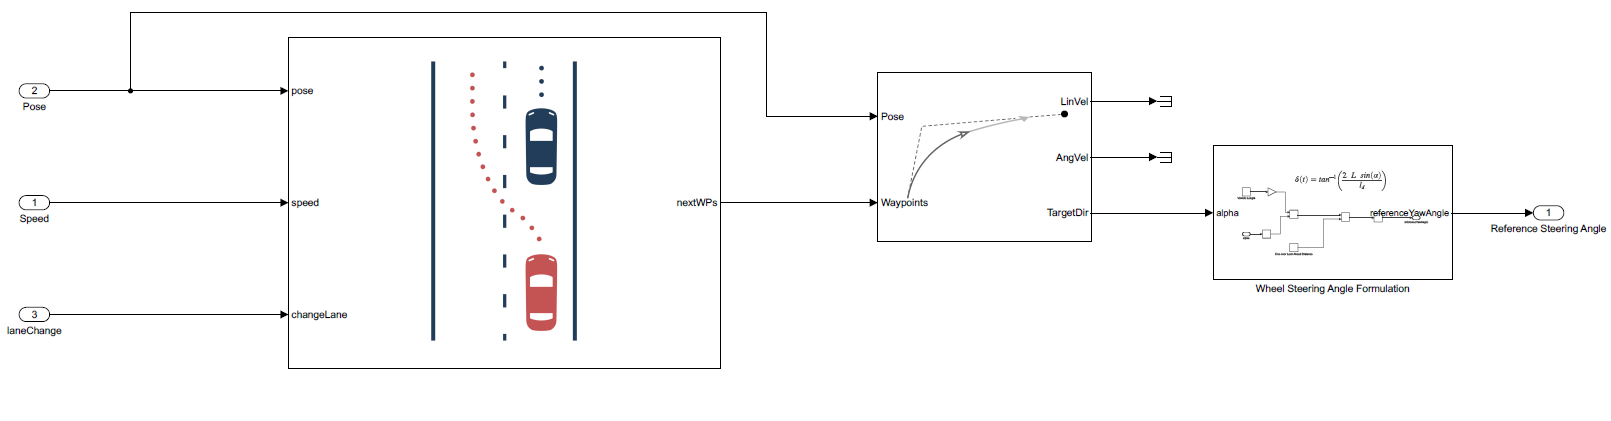

#### Local Trajectory Planning and Lateral Control using the Frenet Coordinate Frame

[Click here to learn more about the local trajectory planners and lateral controllers of autonomous vehicles in MOBATSim.](matlab:open('./VehicleMotionPlanningControl.mlx'))

### Vehicle V2I Output

The current values of position, speed, and path plans of the vehicle are then packed by the V2V communication output component and shared with the rest of the network of connected vehicles. The importance of sharing the path plans of the vehicles is to predict the traffic jams and choose a route that reaches the destination node in the shortest time possible. At this moment, the V2I component is only used to cross intersections. AIM (Autonomous Intersection Management) sends and receives messages and uses its algorithms to decide the right of way for the incoming vehicles.

[Click here to view the source code of the VehicleV2I_Out.m class](matlab:open('..\src\Models and Classes\VehicleV2I_Out.m'))

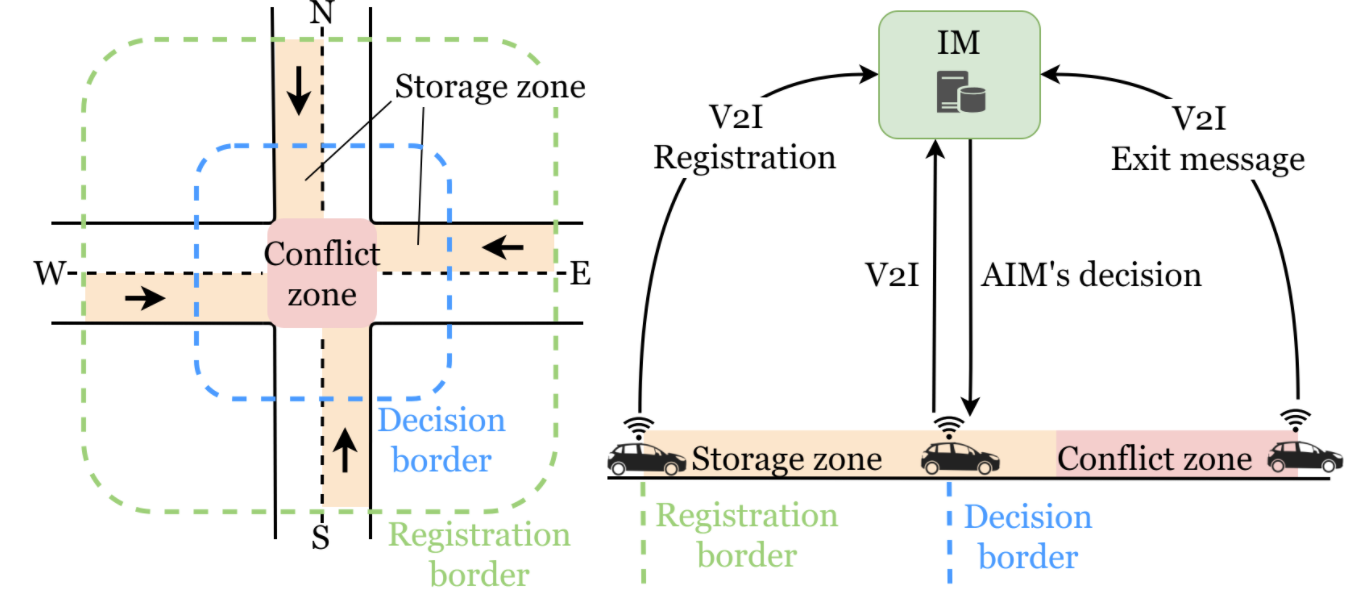

## 2- Data Logging

The orange area just next to the Vehicle Models is where the data is logged using To Workspace blocks. As mentioned before, logged vehicle position, orientation, and speed data are required for further visualization. The logged data is saved in the base workspace as it can be used for a few different visualization options. The coordinate frame is designed according to the Simulink 3D Animation Toolbox, as this was the earliest visualization that MOBATSim had. The coordinate transformation happens by keeping the "x" coordinate the same but replacing the "y" coordinate with zeros, as this refers to height in the 3D world and registering the actual "y" values as "-z" coordinates. More details about the coordinate conversion algorithms will be explained in later chapters.

## 3- Infrastructure (Environment) MATLAB System Block

The whole infrastructure and the environment are implemented as a single MATLAB System Block which takes the Map, Vehicles, and the Intersection Manager objects as arguments. For simulation speed-related reasons, functionally different components are kept in the same function body.

[Click here to view the source code of the Infrastructure.m class](matlab:open('..\src\Models and Classes\Environment\Infrastructure.m'))

However, we can divide the main purposes of this block into three subcategories:

### Dynamic Map Update

After the initialization scripts generate the Map, the initial 2D plot appears as a separate window. When the simulation starts, the positions of the vehicles, along with their planned path and speed information, have to be dynamically plotted. This task is accomplished by the main stepImpl function of the Infrastructure block by taking the Map object by reference and dynamically changes it. Some of these changes include moving vehicles, removing the highlight from the traversed path, changing the highlighted paths if the planned paths change, dynamically updating the vehicle speeds.

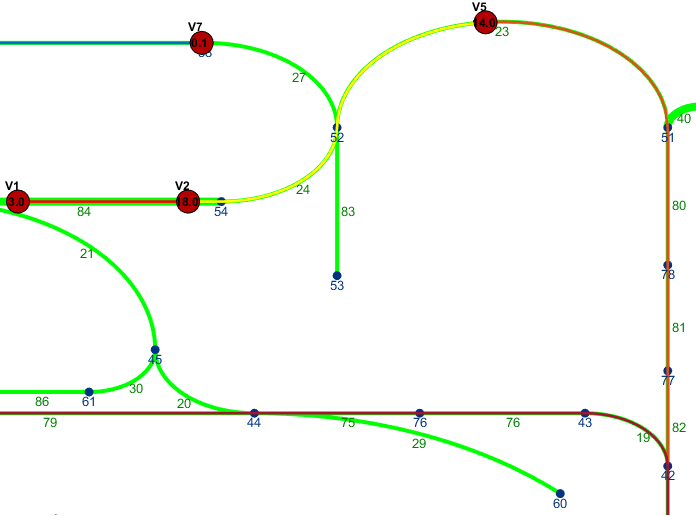

### Collision Detection

The collision detection algorithm works by checking if any two vehicles have a geometrical intersection. As the vehicle positions, orientations and sizes are known, sizes being rectangles, the problem is reduced to checking corner points of a rectangle in the polygon of another rectangle. Since every vehicle is checked to each other, once a collision is detected, namely one or more corners of a rectangle happen to be inside another rectangle, both vehicles' collision properties are set to collide.

The checking of two rectangles with one another happens only if the vehicles are close to each other. Otherwise, it is a waste of computational resources if two rectangles are very far from each other to be checked. In order to make sure that this relatively computationally heavy task of checking collision happens only when necessary, a distance matrix is derived from the current positions. The distance matrix contains the relative distances between the centers of all the vehicles, an NxN matrix with zeros on its main diagonal. Then the threshold value for checking between vehicles that are close enough is chosen according to the L2 norm of the corner points of the rectangle, as it would not be possible otherwise for two rectangles to coincide.

**Check for Collision **- `false`** // Collided **- `false`

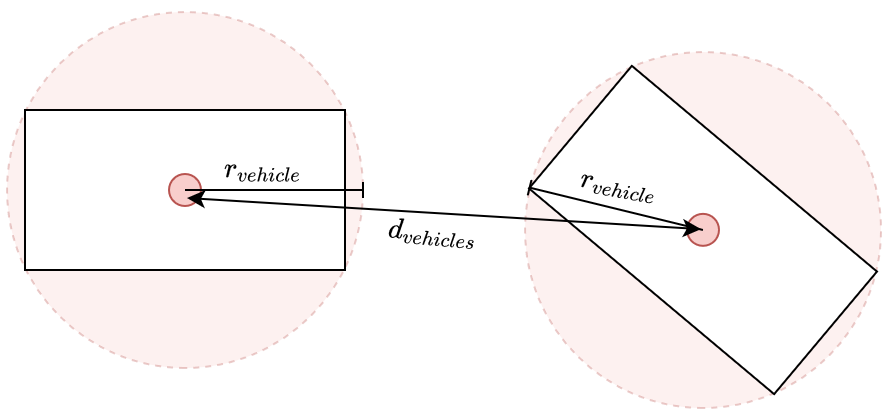

**Check for Collision **- `true`** // Collided **- `false`

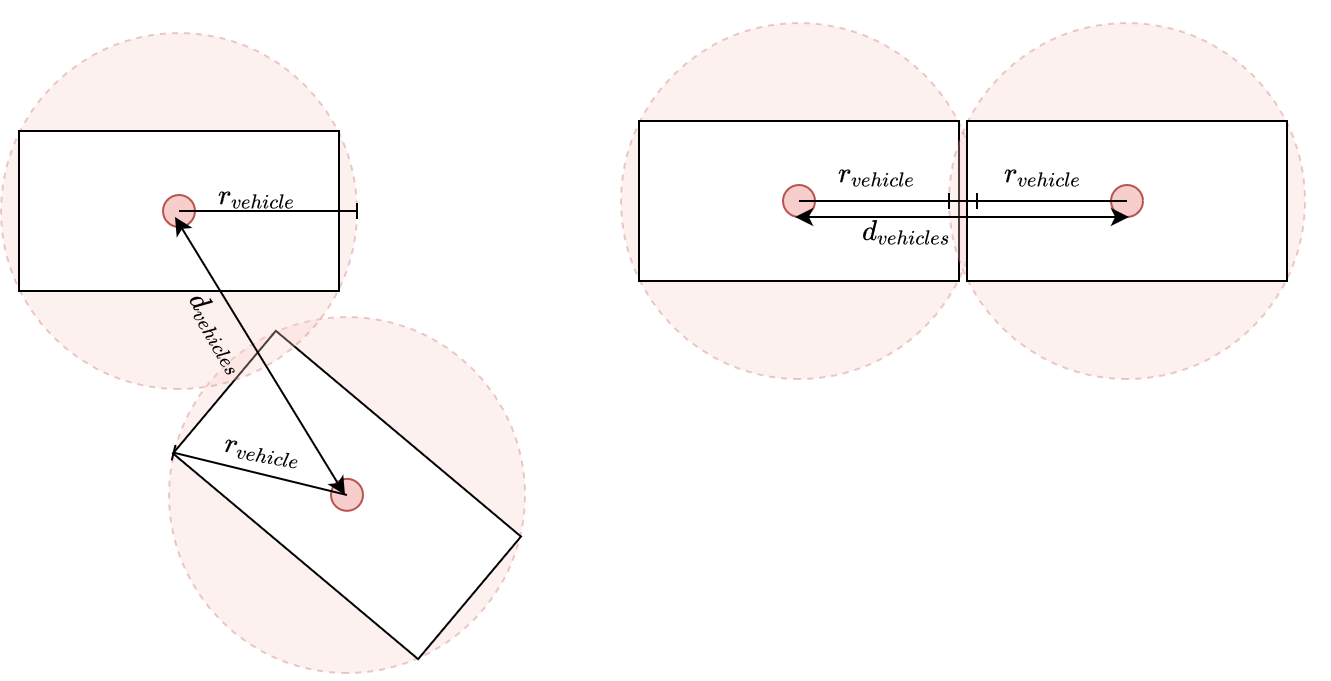

**Check for Collision **- `true`** // Collided **- true

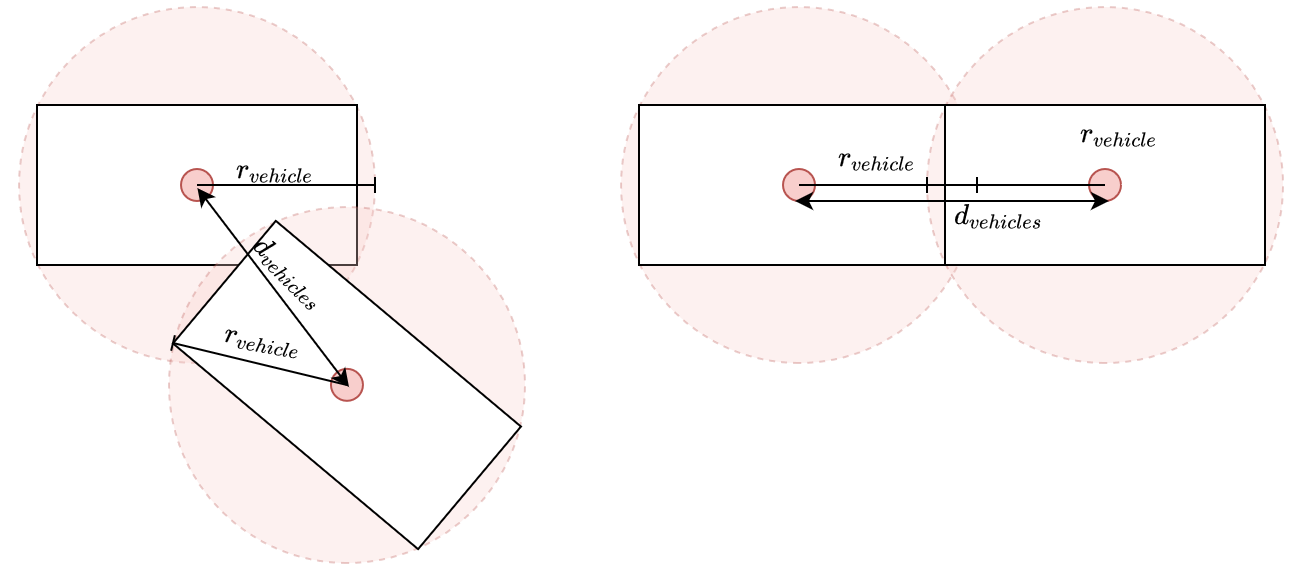

Once a geometric intersection between polygons is detected, these two vehicles are stopped immediately by turning the status.isCollided state from `false` to `true`. As the collision status changes, the vehicle speeds are also set to zero, and both vehicles stop right away without any drag.

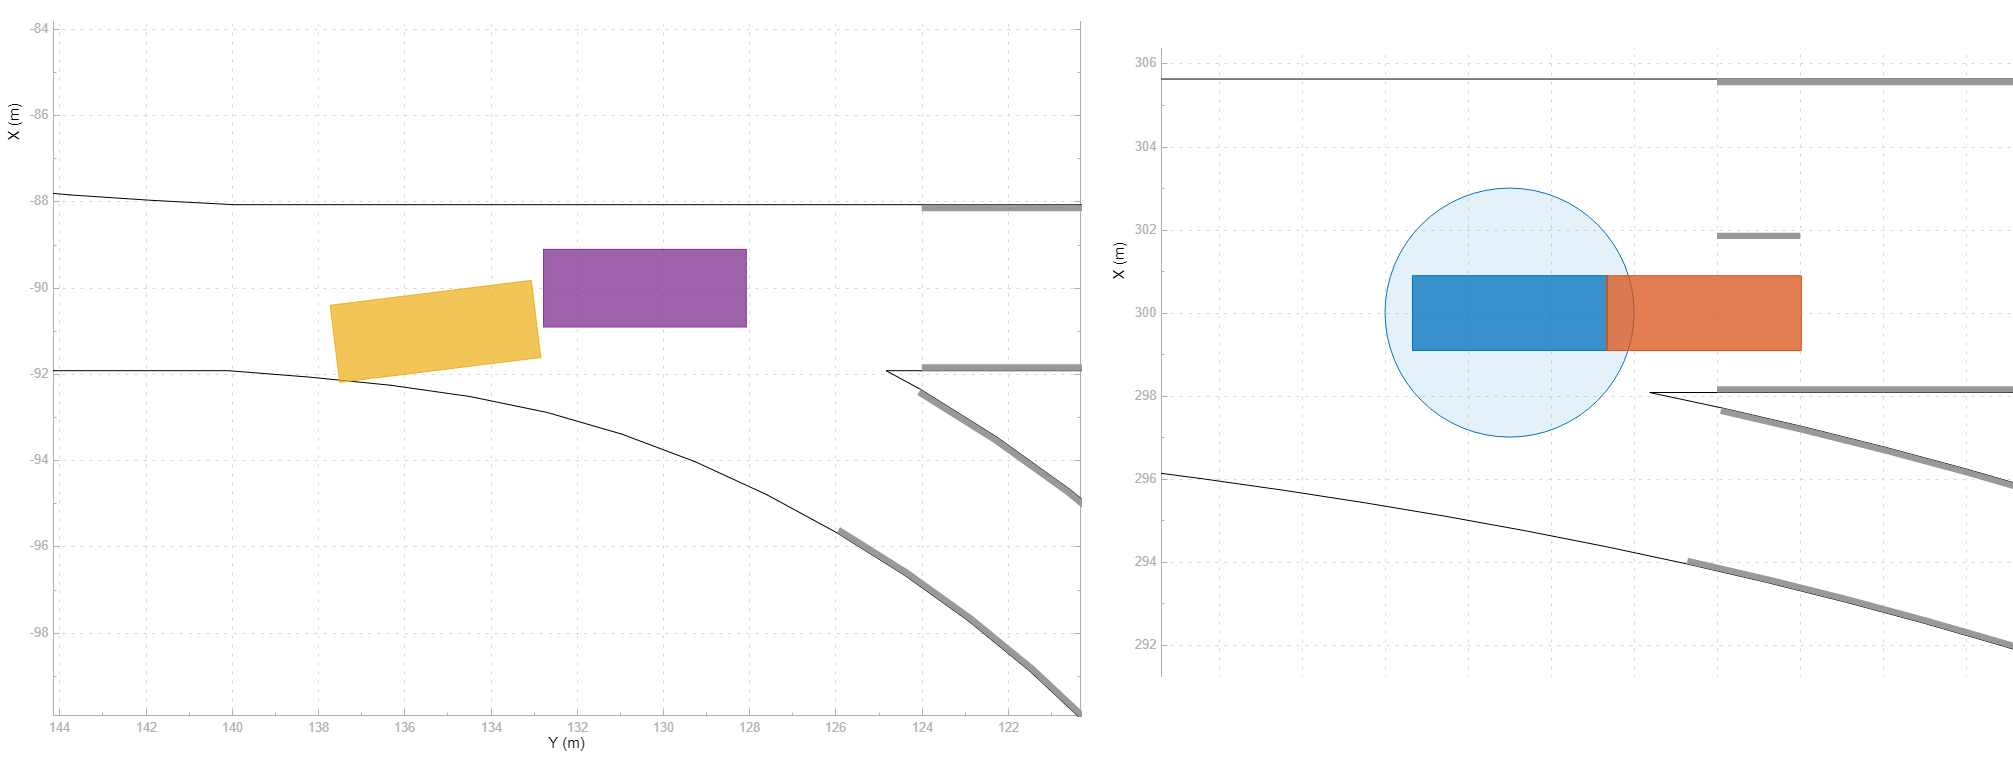

### **Autonomous Intersection Management**

The only Simulink port for the input of the Infrastructure block is the **V2I data** obtained from the vehicles. V2I data is only obtained from vehicles that are getting close to an intersection and sending a message to the intersection manager, stating their desired paths and asking for the **pass** or **stop** signal. The autonomous intersection manager has a few modes like cyclic traffic lights, first-come-first-serve, or the intelligent manager algorithm. By default, the intelligent manager decides the passing orders of the vehicles according to an objective function that tries to minimize the total time spent in the intersection for vehicles. For example, a slow vehicle that asks for permission first might be commanded to stop, and instead, a faster vehicle that asks for permission later is allowed to pass first. An array of these pass/stop signals are then created as an output of the block.

[Click here to view the source code of the CrossroadUnit.m class](matlab:open('..\src\Models and Classes\Environment\CrossroadUnit.m'))

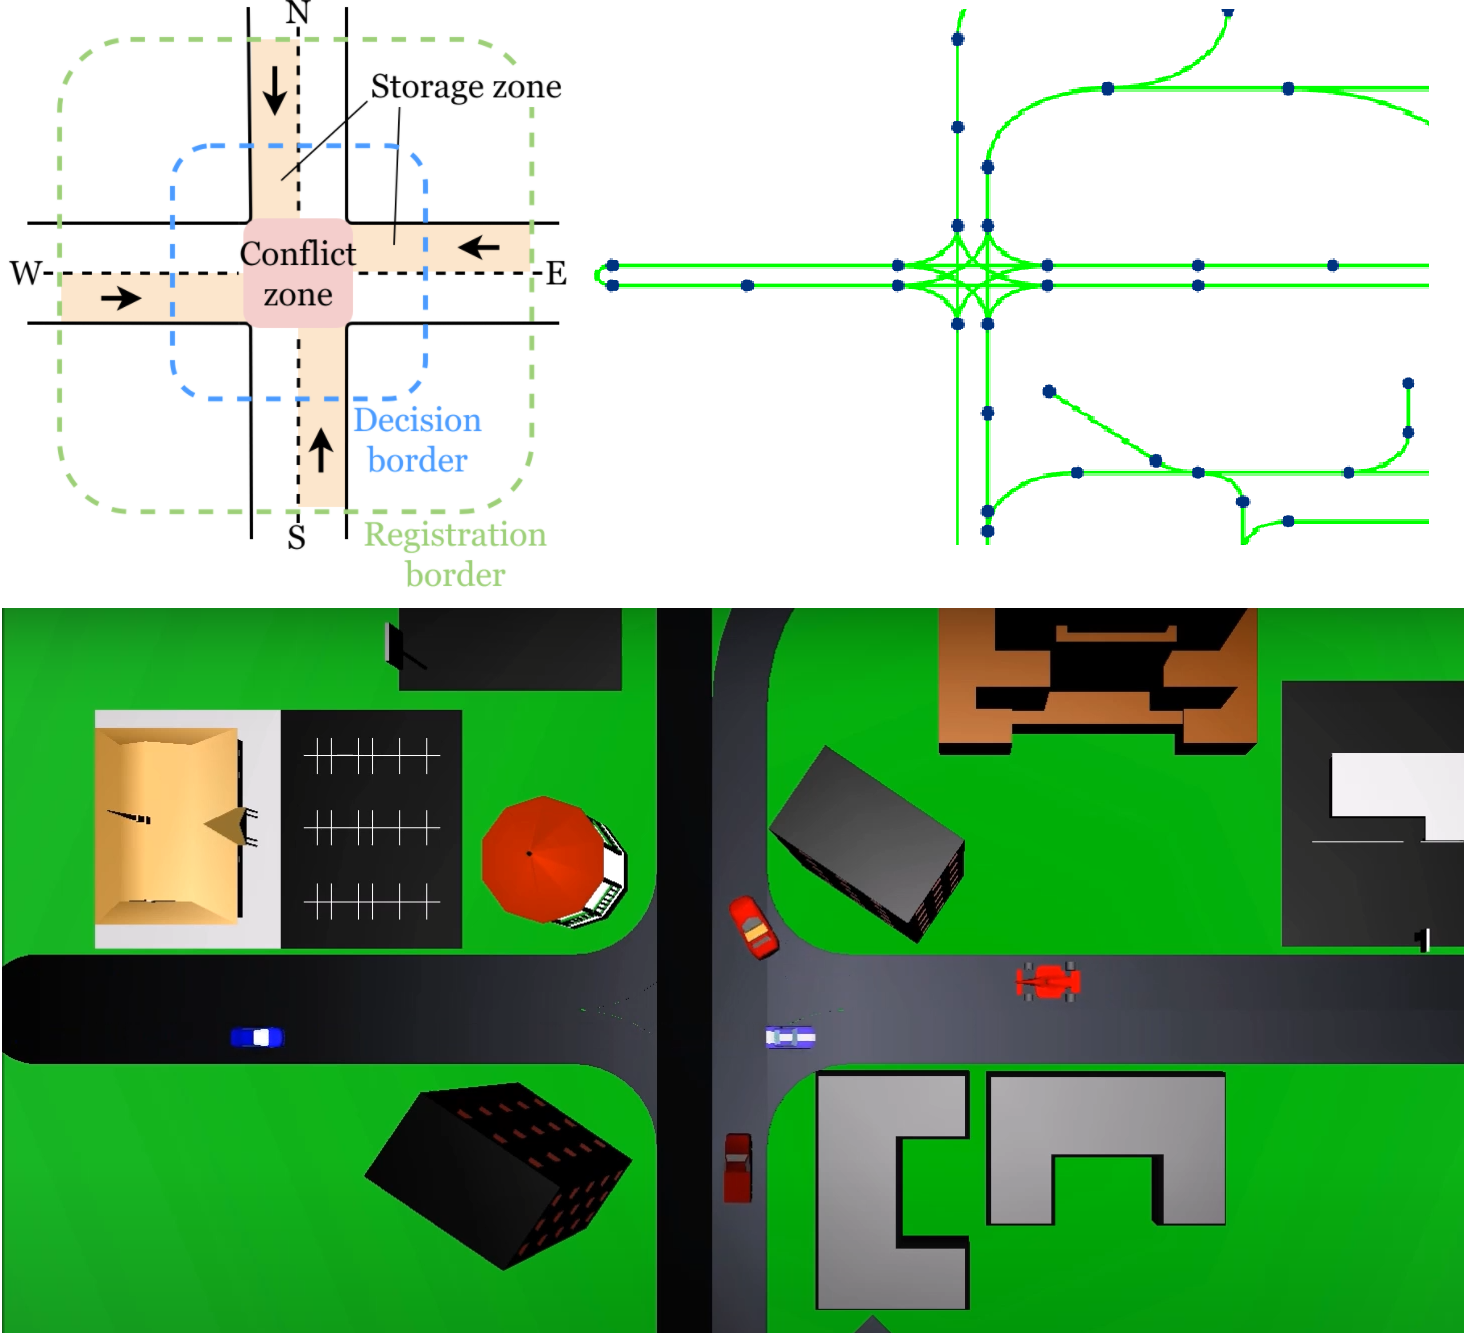

More details about the autonomous manager are coming soon.

## 4- I2V Interface

The array of pass/stop signals coming from the intersection manager is then taken by the I2V block as an input. The only task of this block is to assign the commands that come from the Infrastructure block to relevant Vehicles.

[Click here to view the source code of the I2V.m class](matlab:open('..\src\Models and Classes\I2V.m'))

## 5- Library

The library was first created as a subsystem with blocks that were commented out. It serves as a library and is still kept commented-out if the user wants to check the initial values and parameters. However, with the new version of MOBATSim, a library of the used blocks is created and appears in the **Simulink Library Browser**. By clicking on the **Simulink Library Browser** from the top pane of the **main Simulink model**, the **MOBATSim Librar**y can be seen in the list. This library would be most helpful in testing out new algorithms or controllers that serve a similar purpose. For example, a vehicle's **Lateral Controller, Path Planner, **or **Platoon Controller** can be changed with another type of block available in the library.

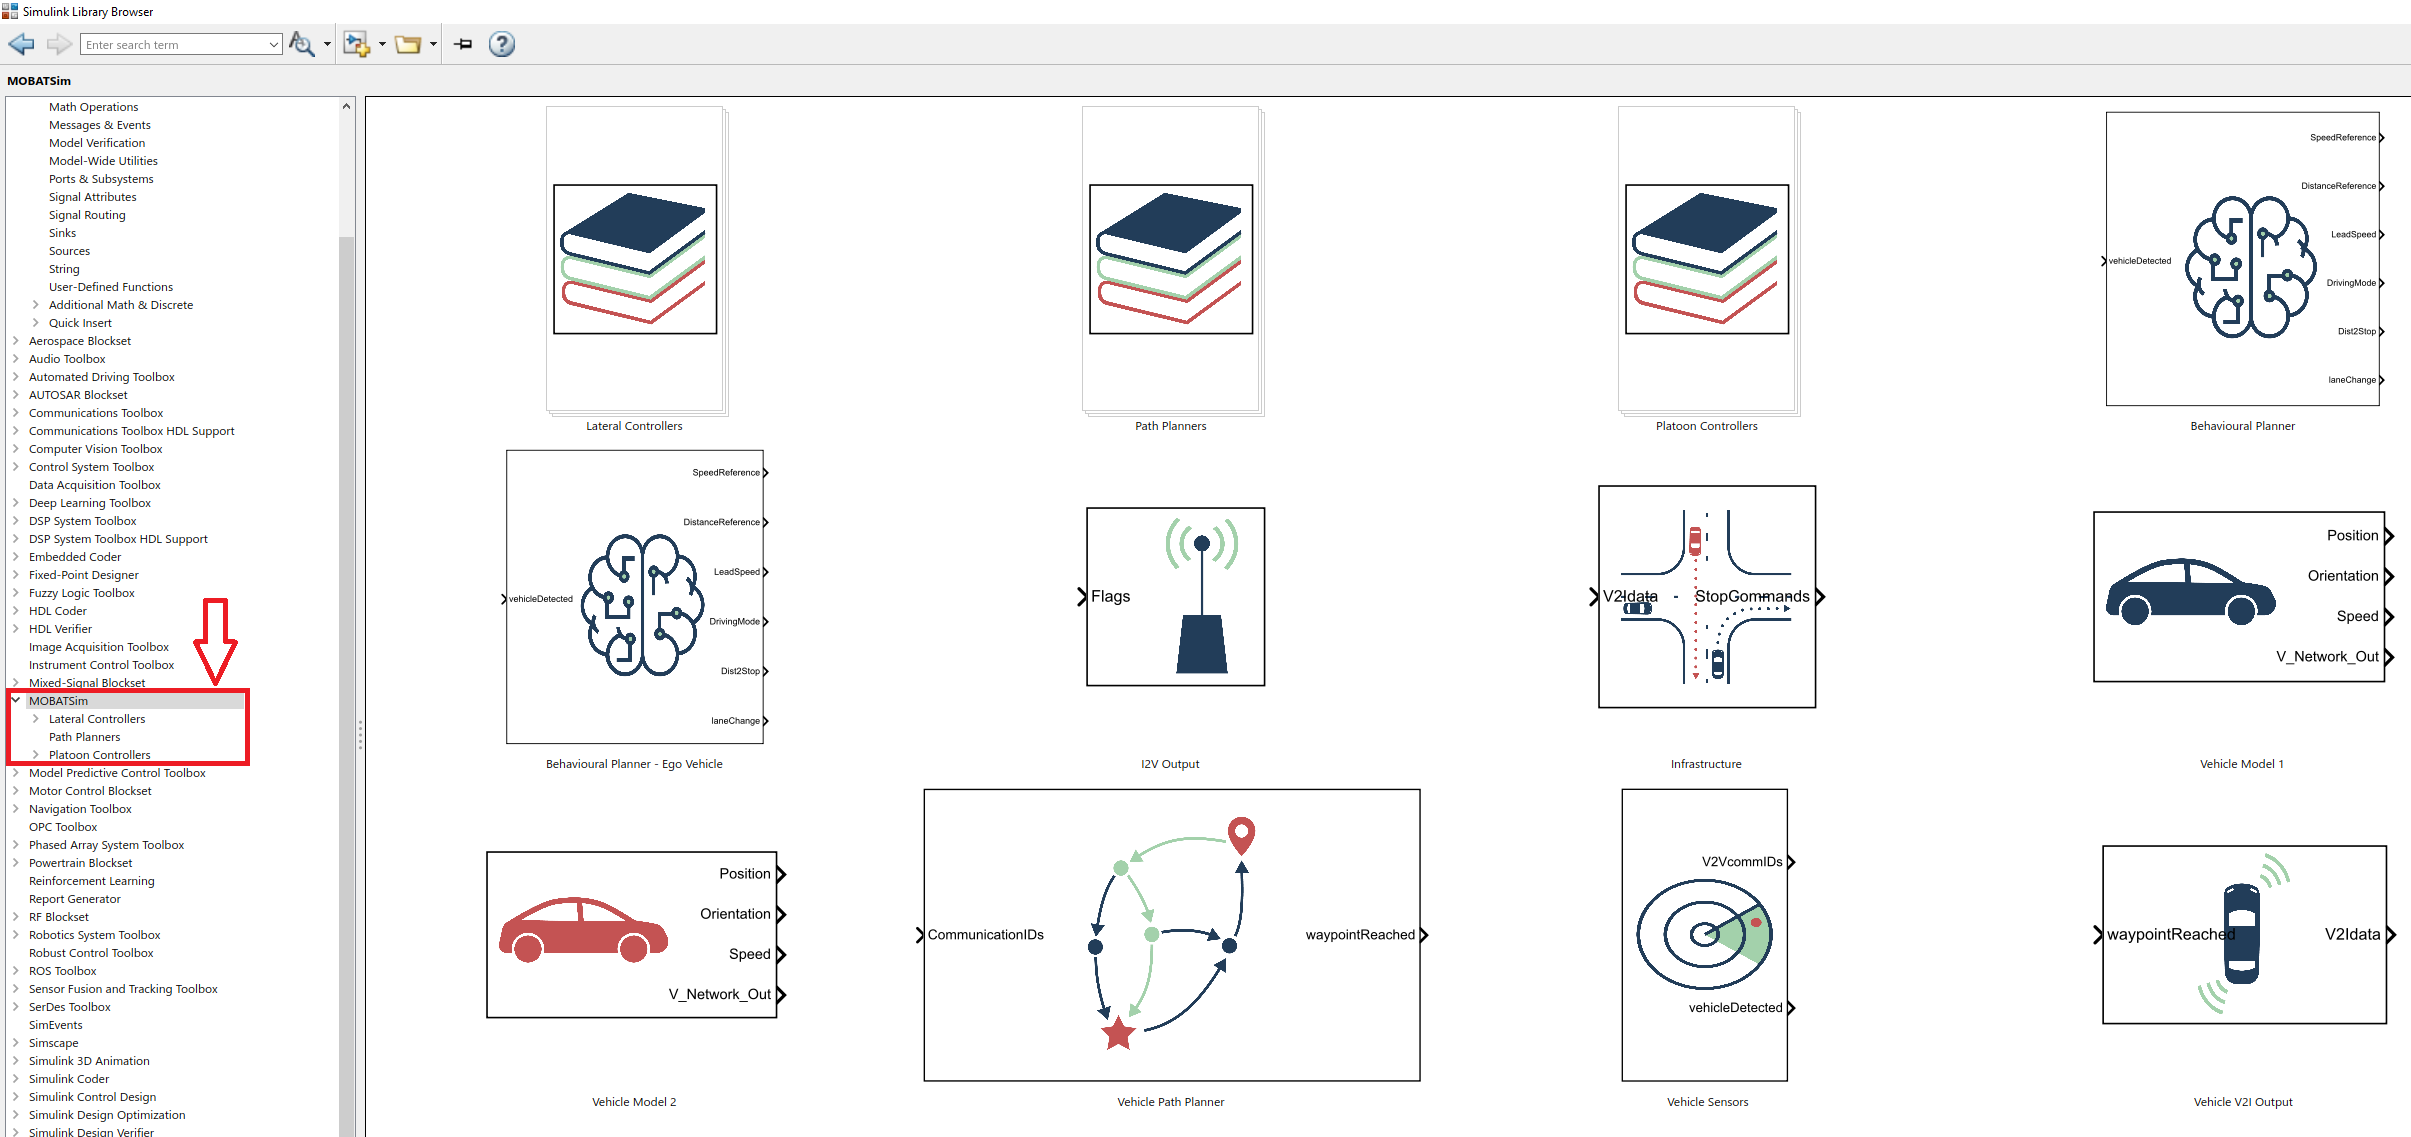

The commented-out Library subsystem block in the main Simulink model bottom right corner will be removed in the next version, and only the **Simulink Library Browser - MOBATSim Library** will be available for use.

## Simulink Block Execution Order

When the simulation starts, the model takes time to compile and then start executing the Simulink blocks. As mentioned before, the MATLAB System blocks use interpreted execution to use some specific MATLAB commands. The MATLAB System Blocks used in the Simulink are given below according to their execution order. Note that the MATLAB System blocks inside the vehicle subsystems run for every single vehicle.

- *VehicleSensors.m*

- *VehiclePathPlanner.m*

- *VehicleV2I_Out.m*

- *Infrastructure.m* **(executes once for the model each sample time)**

- *I2V.m* **(executes once for the model each sample time)**

- *VehicleDrivingMode.m*

- *Stanley_RefPoseGenerator.m* (Vehicle local trajectory planner)

- *VehicleSafetyFilter.m*

The execution order of the Simulink blocks, as well as the sample times for each signal, can be viewed from the top pane **DEBUG > Information Overlays >**  as shown below:

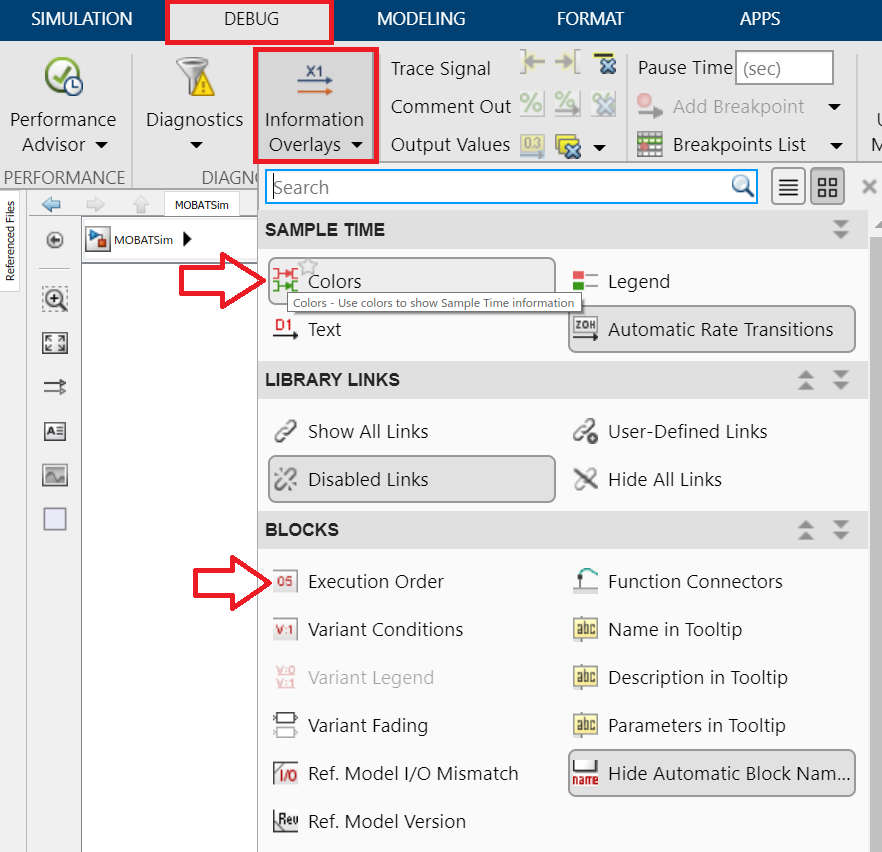

The dependencies for the main Simulink model during the runtime are shown below.

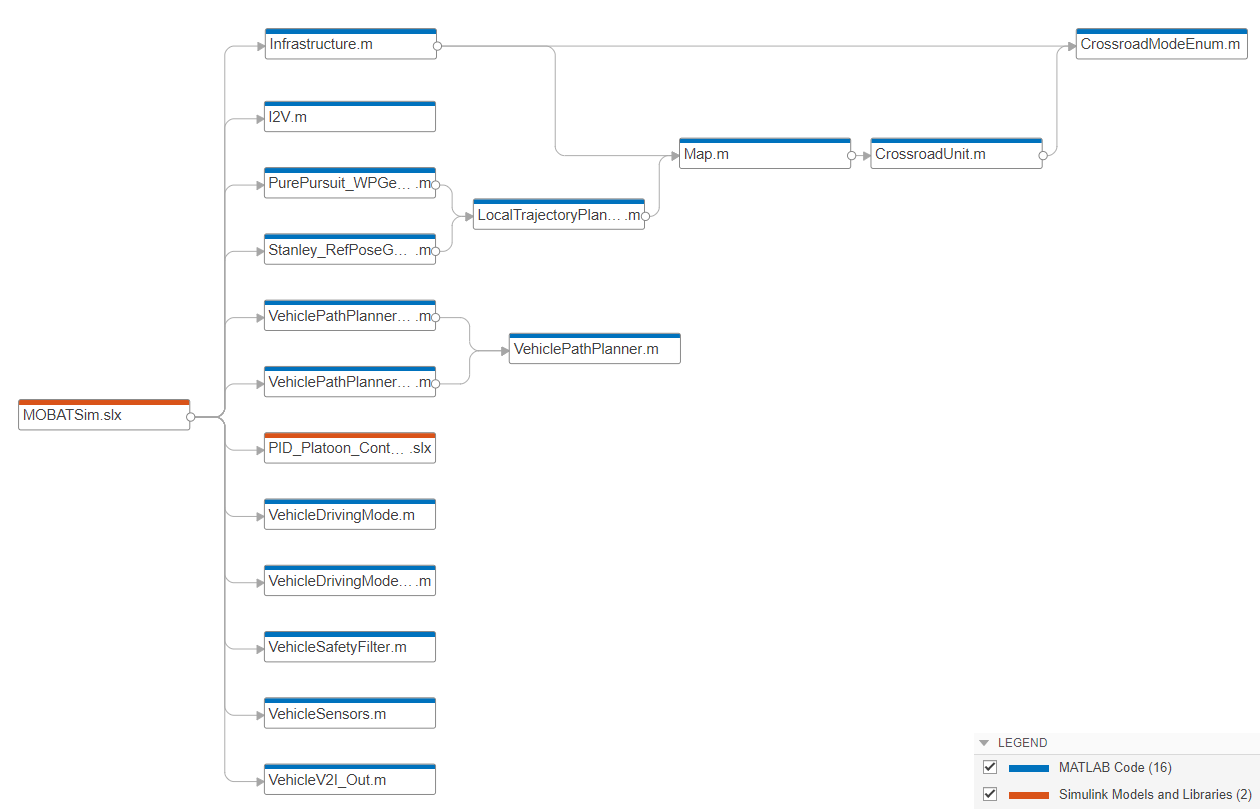

## SuperClass - Inheritance Structure

In MOBATSim, two Simulink superclasses (used as MATLAB System blocks) define the blueprint for any child class that inherits from them.

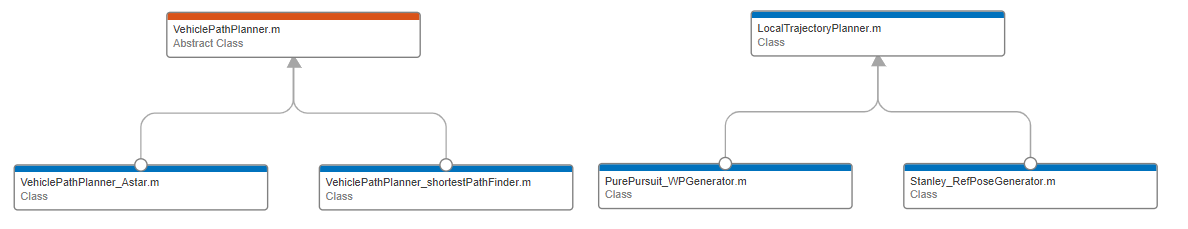

More information about Object-Oriented Programming in MATLAB: [https://www.mathworks.com/products/matlab/object-oriented-programming.html](https://www.mathworks.com/products/matlab/object-oriented-programming.html)

# ---------------------------------------------------------------------------------

# Adding the 11th Vehicle to MOBATSim

A new tutorial will be added soon...